Matlab project :)

**Specific requirements:**

- Introduce the source, format, and background of the data set, what kind of statistical/machine learning task(s) it is originally created for, and websites, papers, or competitions that use the data set.

- Report summary information of the data set, such as #instances, #features (categorical, or numerical), % missing values (if any).

- Visualization of single or small subsets of variables. 

                - Visualization based on 1 - 3 variables at a time should still be performed:

                        - Single categorical variable(s)

                        - Selected single numerical variables

                        - Selected pairs of variables (both numerical, one numerical + one categorical)

                        - Selected triples of variables (all numerical, two numerical + one categorical)

                        - (if we add reviews) Documents data (refer to data_plotting4.m)

- Feature scaling (if the magnitudes of the variables are very different, normalize them to a common range such as [0,1], or [-1,1])

- Dimension reduction methods to be applied to the data set (for simultaneous visualization of all the numerical variables):  

- Linear, unsupervised: PCA

- Linear, supervised: LDA

- Nonlinear, unsupervised, global: MDS (with any metric except Euclidean) 

- Nonlinear, unsupervised, local: Laplacian Eigenmaps, or another nonlinear one (such as LLE). In the latter case, you must provide a brief, clear description of the algorithm regarding how it works.

Project Steps:

- clean the data

- summary statistics, and visualization of single or small subsets of variables. 

- put all numerical data in a matrix and perform feature scaling

- dimension reduction methods

## **Loading the Data**

clear;
opts = delimitedTextImportOptions("NumVariables", 13);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["App", "Category", "Rating", "Reviews", "Size", "Installs", "Type", "Price", "ContentRating", "Genres", "LastUpdated", "CurrentVer", "AndroidVer"];
opts.VariableTypes = ["string", "categorical", "double", "double", "string", "string", "categorical", "string", "categorical", "categorical", "datetime", "string", "string"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["App", "Size", "Installs", "Price", "CurrentVer", "AndroidVer"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["App", "Category", "Size", "Installs", "Type", "Price", "ContentRating", "Genres", "CurrentVer", "AndroidVer"], "EmptyFieldRule", "auto");
opts = setvaropts(opts, "LastUpdated", "InputFormat", "MMMM d, yyyy");
opts = setvaropts(opts, ["Rating", "Reviews"], "ThousandsSeparator", ",");

% Import the data
data = readtable("data/googleplaystore.csv", opts);
clear opts % clear temporary variables

## **Cleaning the data**

Removing Missing Variables

size(data) % 13 vairables, 10841 apps

ans =        10841          13


Missing data by variable

app = sum(ismissing(data.App));
category = sum(ismissing(data.Category));
rating = sum(ismissing(data.Rating));
reviews = sum(ismissing(data.Reviews));
Size = sum(ismissing(data.Size));
installs = sum(ismissing(data.Installs));
type = sum(ismissing(data.Type));
price = sum(ismissing(data.Price));
contentRating = sum(ismissing(data.ContentRating));
genres = sum(ismissing(data.Genres));
lastUpdated = sum(ismissing(data.LastUpdated));
currentVer = sum(ismissing(data.CurrentVer));
androidVer = sum(ismissing(data.AndroidVer));
table(app, category, rating, reviews, Size, installs, type, price, ...
    contentRating, genres, lastUpdated, currentVer, androidVer)

ans = 1×13 table
    app    category    rating    reviews    Size    installs    type    price    contentRating    genres    lastUpdated    currentVer    androidVer
    ___    ________    ______    _______    ____    ________    ____    _____    _____________    ______    ___________    __________    __________

     0        0         1474        1        0         0         0        0            1            0            1             0             1     


clear Size installs price app rating category reviews type contentRating genres lastUpdated currentVer androidVer;
data( any(ismissing(data),2), :) = [];
size(data)

ans =         9366          13


data(find(string(data.Size)=='Varies with device'),:) = []; % removing weird size
size(data) % size after deleting a ton of variables.

ans =         7729          13


Fixing data types and removing special characters

% data.Sizes
charSize = strtrim(data.Size);
msize = charSize(endsWith(charSize,'M'));
charSize_m = cellstr(string(str2double(string(strrep(msize,'M', '')))*1000));
charSize(endsWith(charSize,'M')) = charSize_m;
SizeOnlyk = strrep(charSize,'k', '');
data.Size_K = SizeOnlyk;
data.Size_K = str2double(string(data.Size_K));
% also add MB data
data.Size_MB = data.Size_K * 0.001

data = 7729×15 table
                            App                                Category       Rating     Reviews       Size       Installs       Type    Price    ContentRating             Genres                 LastUpdated             CurrentVer           AndroidVer      Size_K    Size_MB
    ____________________________________________________    ______________    ______    __________    ______    _____________    ____    _____    _____________    _________________________    __________________    ____________________    


% data.Installs
data.Installs = str2double(strrep(data.Installs,'+',''));

% data.Price
data.Price = str2double(strrep(data.Price,'$',''));

% cleaning up
clear charSize charSize_m msize SizeOnlyk;

## Outliers

p = sort(data.Price,'descend');
p(1:20)

ans =   400.0000
  399.9900
  399.9900
  399.9900
  399.9900
  399.9900
  399.9900
  399.9900
  399.9900
  399.9900


There are 15 apps that are between $399.99 to $299.99 and two apps at $80, the rest are under $40.

We are going to remove the applications that cost over $40.

data(find(data.Price > 40),:)

ans = 17×15 table
                  App                   Category     Rating    Reviews     Size     Installs    Type    Price     ContentRating       Genres           LastUpdated       CurrentVer      AndroidVer      Size_K    Size_MB
    ________________________________    _________    ______    _______    ______    ________    ____    ______    _____________    _____________    _________________    __________    ______________    ______    _______

    "Vargo Anesthesia Mega App"  

data(find(data.Price > 40),:) = [];

Visualization plan

Summary statistics: (top 5 we create plots for)

- maximum price (top 5)

- average price of paid games

- maximum installs (top 5)

- average installs

- average size

- average rating

- top 5 ratings

- average reviews

- top 5 reviews

## Single Numerical Variable Plots

Shayna

### Rating

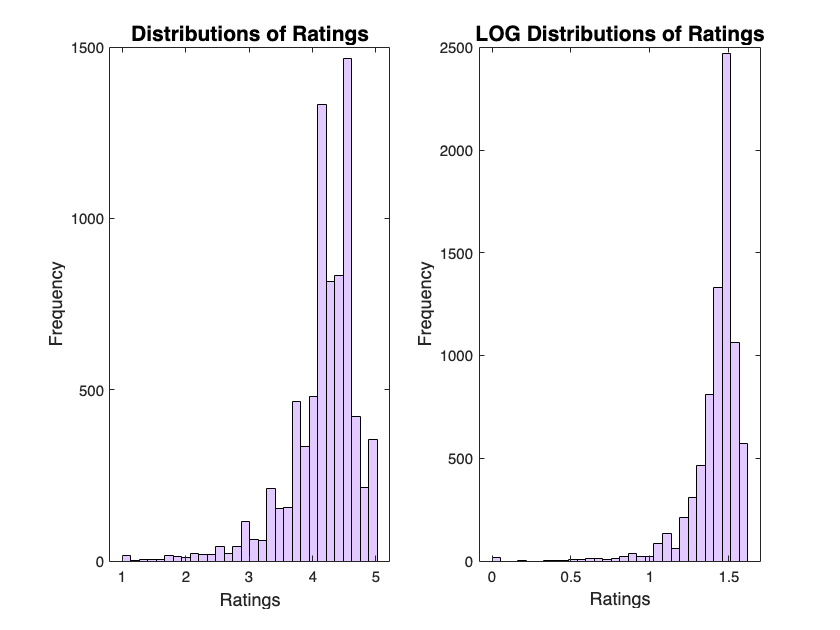

figure;
% Ratings plot
subplot(1,2,1)
histogram(data.Rating,30,FaceColor='#CFA5FF')
title("Distributions of Ratings",FontSize=14)
xlabel("Ratings",FontSize=12)
ylabel("Frequency",FontSize=12)
% Ratings plot
subplot(1,2,2)
histogram(log(data.Rating),30,FaceColor='#CFA5FF')
title("LOG Distributions of Ratings",FontSize=14)
xlabel("Ratings",FontSize=12)
ylabel("Frequency",FontSize=12)

This data will not be log transformed

### Reviews

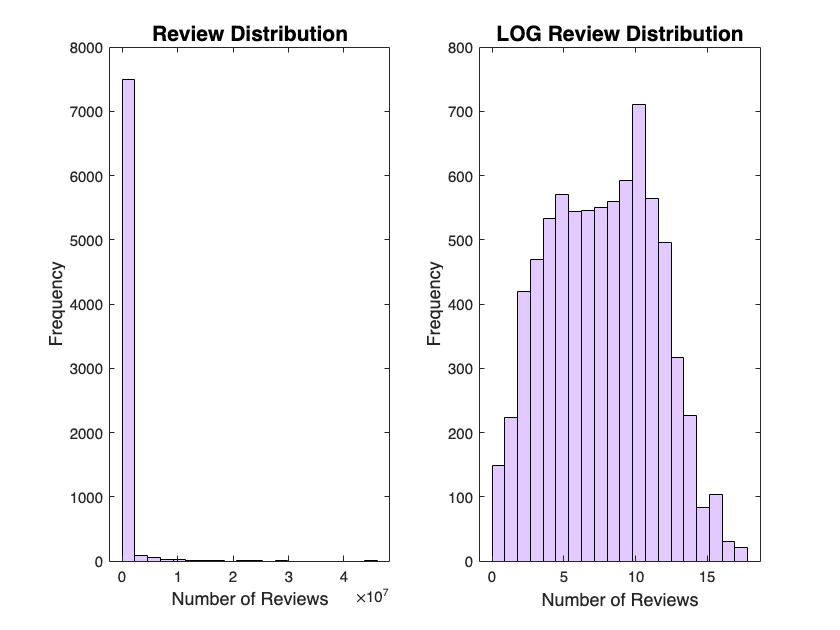

% Reviews plot
subplot(1,2,1)
histogram(data.Reviews,20,FaceColor='#CFA5FF')
title("Review Distribution",FontSize=14)
xlabel("Number of Reviews",FontSize=12)
ylabel("Frequency",FontSize=12)
% Reviews plot
subplot(1,2,2)
histogram(log(data.Reviews),20,FaceColor='#CFA5FF')
title("LOG Review Distribution",FontSize=14)
xlabel("Number of Reviews",FontSize=12)
ylabel("Frequency",FontSize=12)

### Size

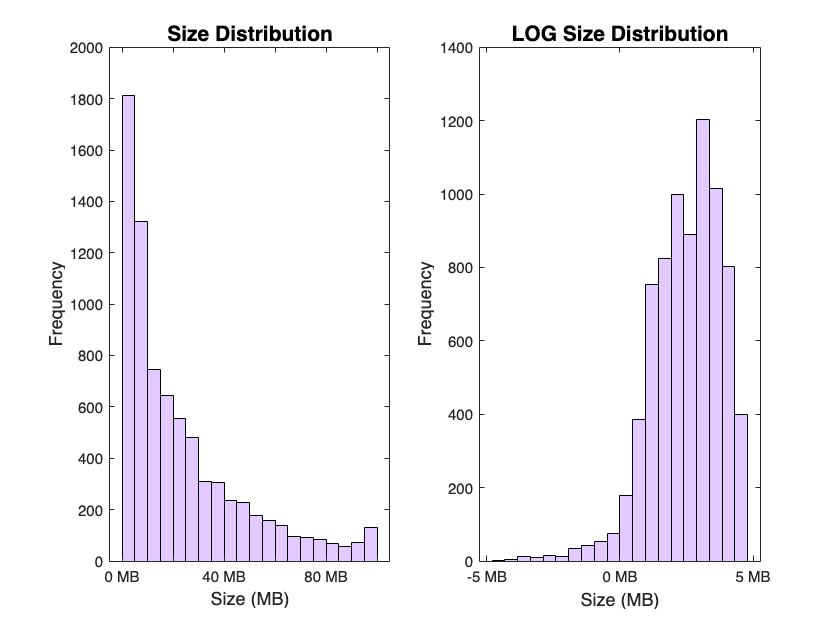

% Size plot
subplot(1,2,1)
histogram(data.Size_MB,20,FaceColor='#CFA5FF')
title("Size Distribution",FontSize=14)
xlabel("Size (MB)",FontSize=12)
ylabel("Frequency",FontSize=12)
xtickformat('%g MB')
% Size plot
subplot(1,2,2)
histogram(log(data.Size_MB),20,FaceColor='#CFA5FF')
title("LOG Size Distribution",FontSize=14)
xlabel("Size (MB)",FontSize=12)
ylabel("Frequency",FontSize=12)
xtickformat('%g MB')

### Installs

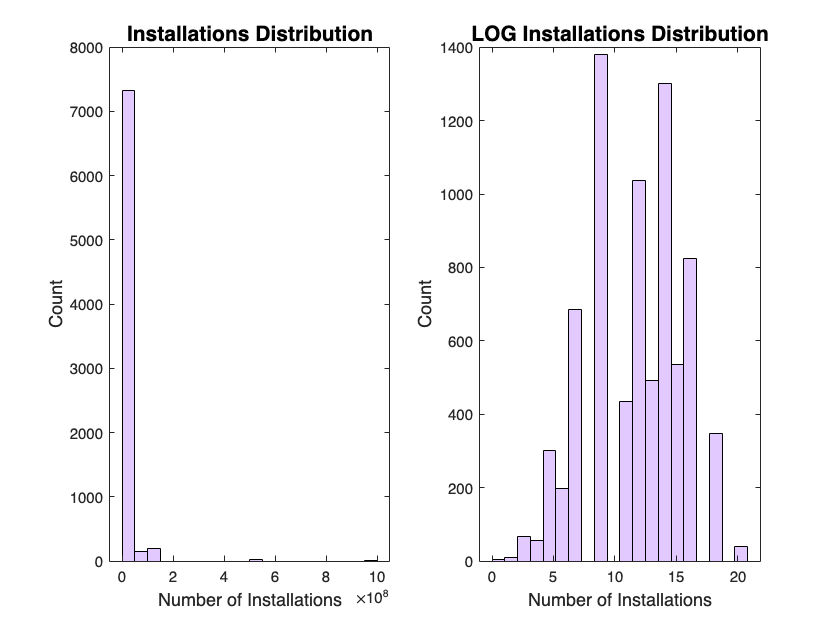

% installs plot is not good maybe we don't include it
subplot(1,2,1);
histogram(data.Installs,20,FaceColor='#CFA5FF') % trying different things
title("Installations Distribution",FontSize=14)
xlabel("Number of Installations",FontSize=12)
ylabel("Count",FontSize=12)
% installs plot is not good maybe we don't include it
subplot(1,2,2);
histogram(log(data.Installs),20,FaceColor='#CFA5FF') % trying different things
title("LOG Installations Distribution",FontSize=14)
xlabel("Number of Installations",FontSize=12)
ylabel("Count",FontSize=12)

## Price

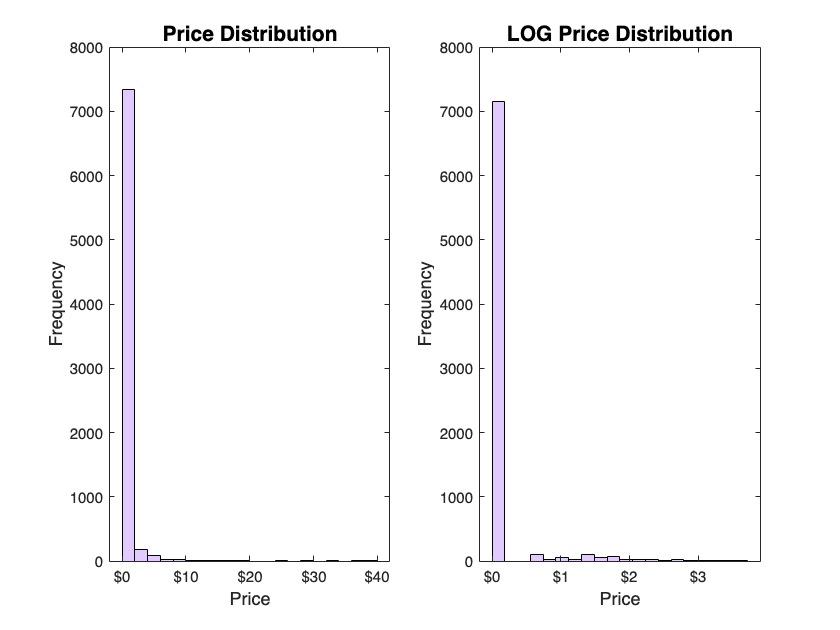

% Price plot
figure;
subplot(1,2,1);
histogram(data.Price,20,FaceColor='#CFA5FF')
title("Price Distribution",FontSize=14)
xlabel("Price",FontSize=12)
ylabel("Frequency",FontSize=12)
xtickformat('$%g')
subplot(1,2,2);
histogram(log(data.Price+1),20,FaceColor='#CFA5FF')
title("LOG Price Distribution",FontSize=14)
xlabel("Price",FontSize=12)
ylabel("Frequency",FontSize=12)
xtickformat('$%g')

## Single Categorical Variable Plots

Tien

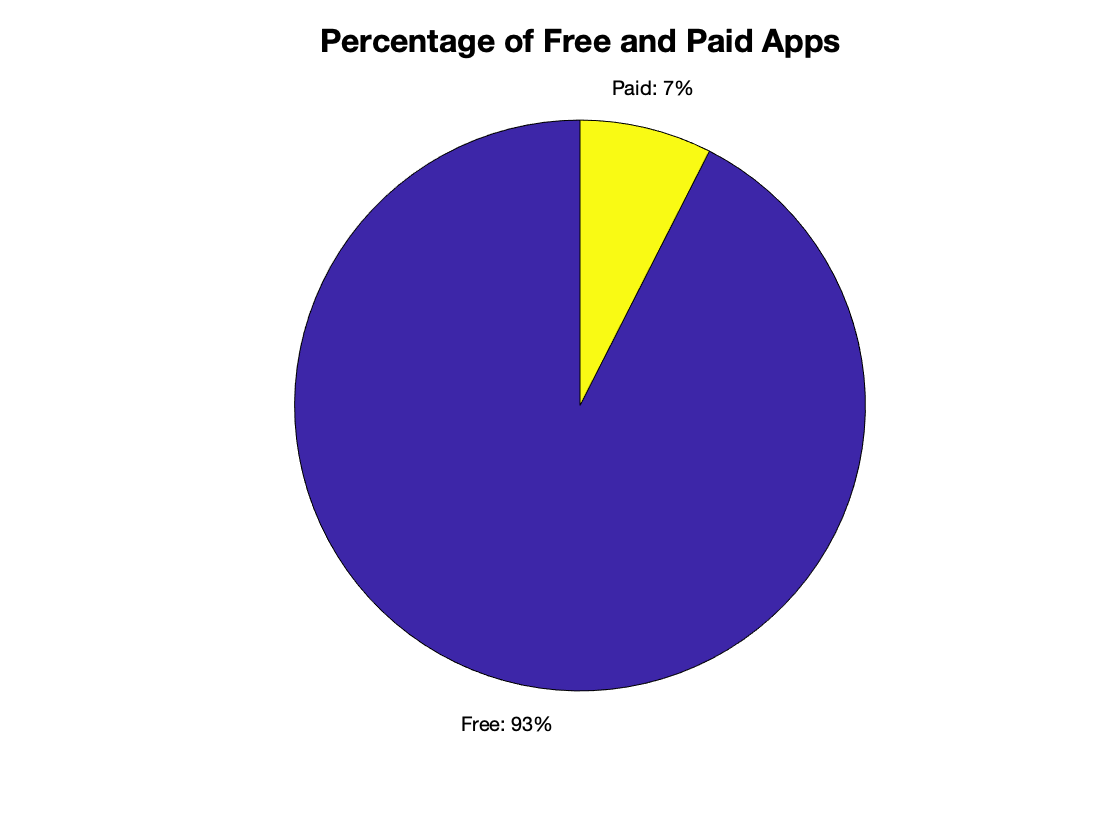

% Type plot
figure;
G1 = groupcounts(data,'Type');
p = pie(G1.Percent);
pText = findobj(p,'Type','text');
percentValues = get(pText,'String'); 
txt = {'Free: ', 'Paid: '};
combinedtxt = strcat(txt,percentValues'); 
pText(1).String = combinedtxt(1);
pText(2).String = combinedtxt(2);
title('Percentage of Free and Paid Apps', 'fontsize',16);

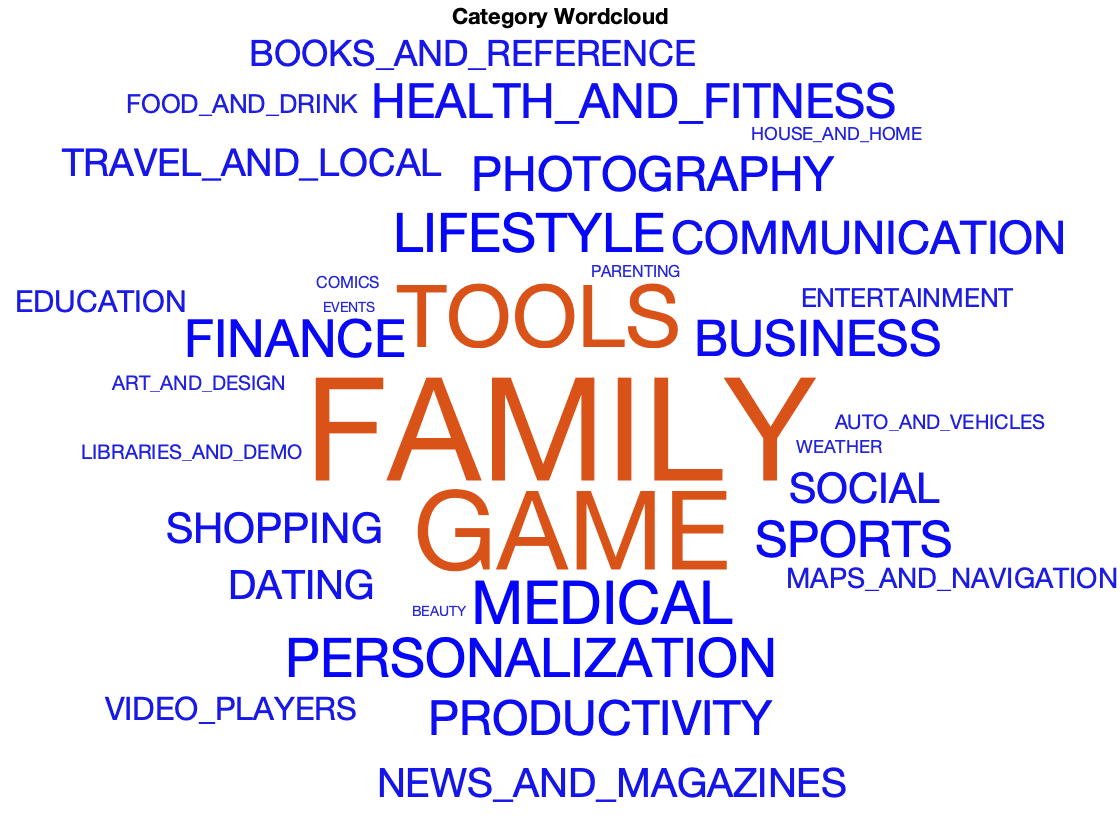


% Category word cloud
figure;
wordcloud(data.Category,'Color','blue');
title('Category Wordcloud')

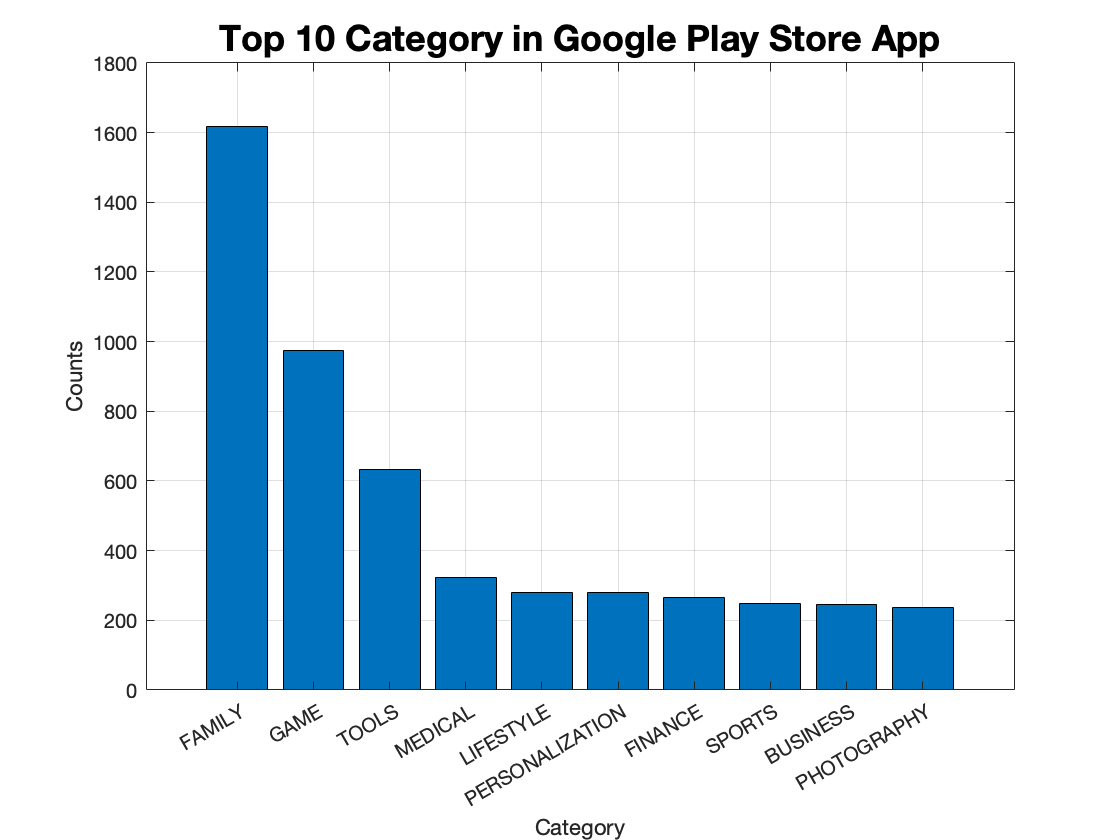


% Category Plot
figure;
Category = categories(data.Category);
Count = countcats(data.Category);
category_table = table(Category,Count);
category_table = sortrows(category_table,'Count','descend');
top10_category = category_table(1:10,:);
figure
b = bar(top10_category .Count);
xticklabels(top10_category .Category);
ylabel('Counts')
xlabel('Category')
grid on
title('Top 10 Category in Google Play Store App', 'fontsize', 18)

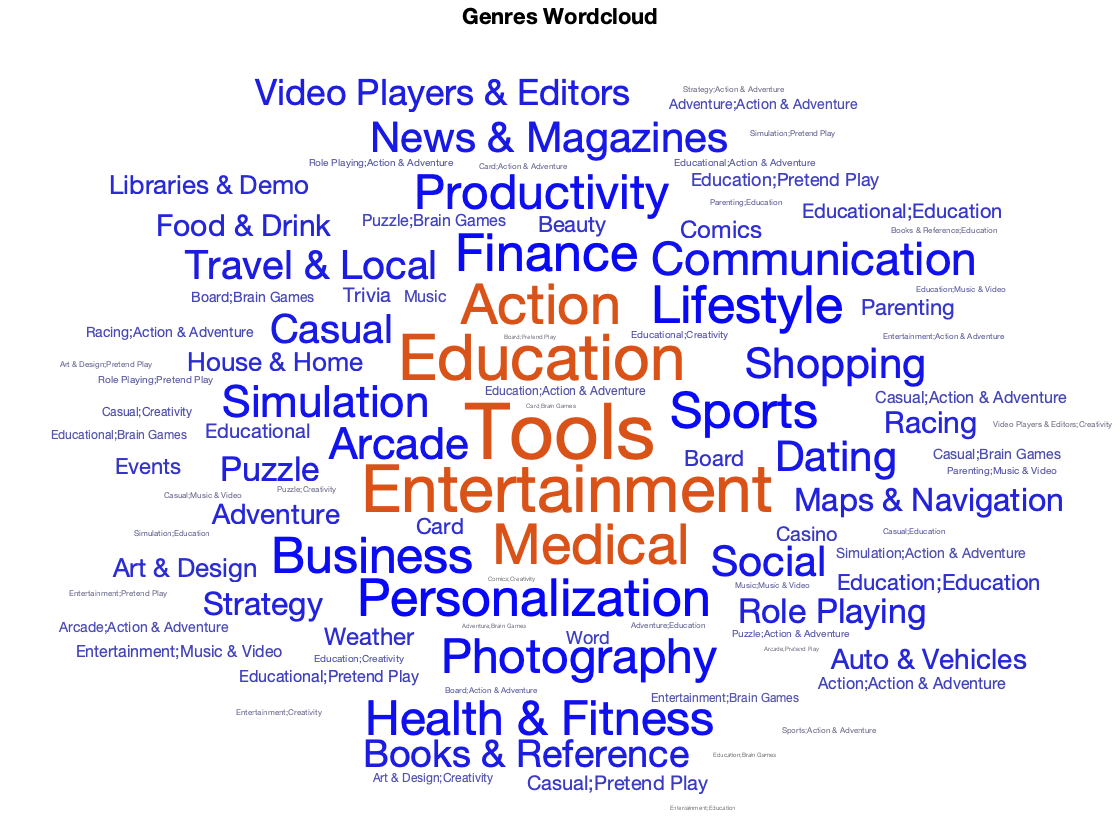


% genres word cloud
figure;
wordcloud(data.Genres,'Color','blue');
title('Genres Wordcloud')

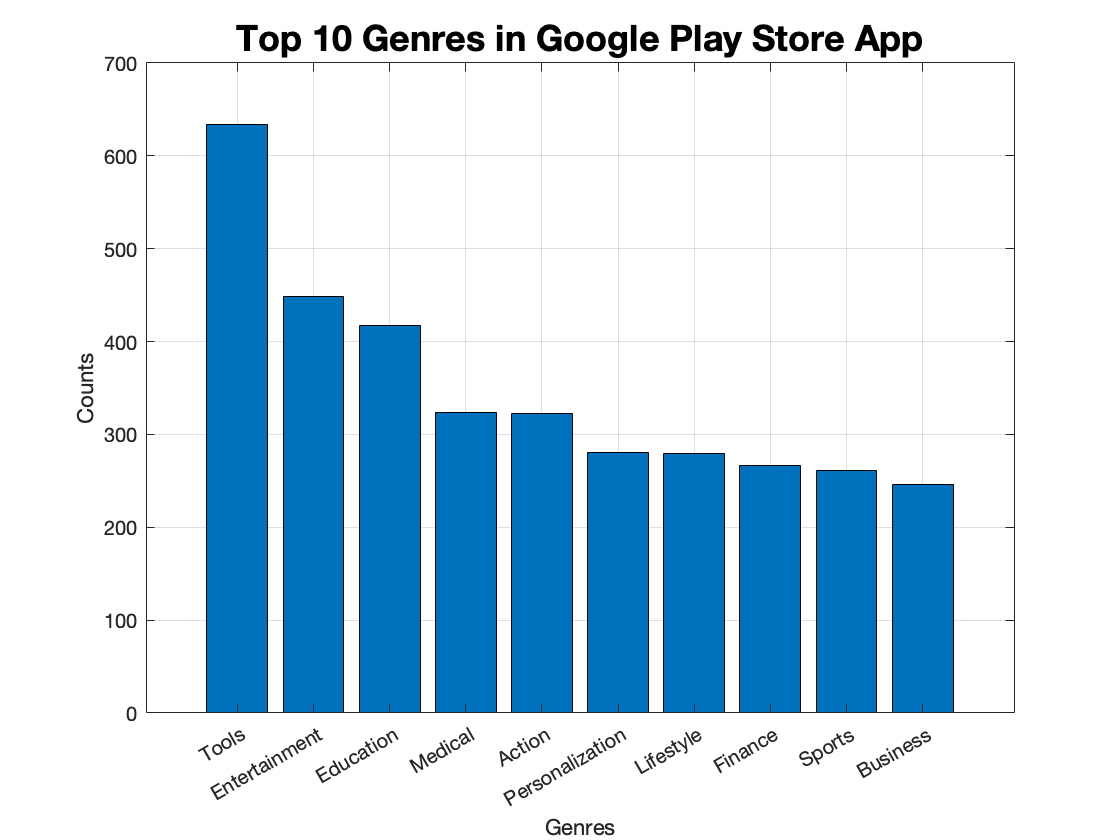


% Genres plot
figure;
Genres = categories(data.Genres);
Count = countcats(data.Genres);
genres_table = table(Genres,Count);
genres_table = sortrows(genres_table,'Count','descend');
top10_genres = genres_table(1:10,:);
figure
b = bar(top10_genres.Count);
xticklabels(top10_genres.Genres);
ylabel('Counts')
xlabel('Genres')
grid on
title('Top 10 Genres in Google Play Store App', 'fontsize', 18)

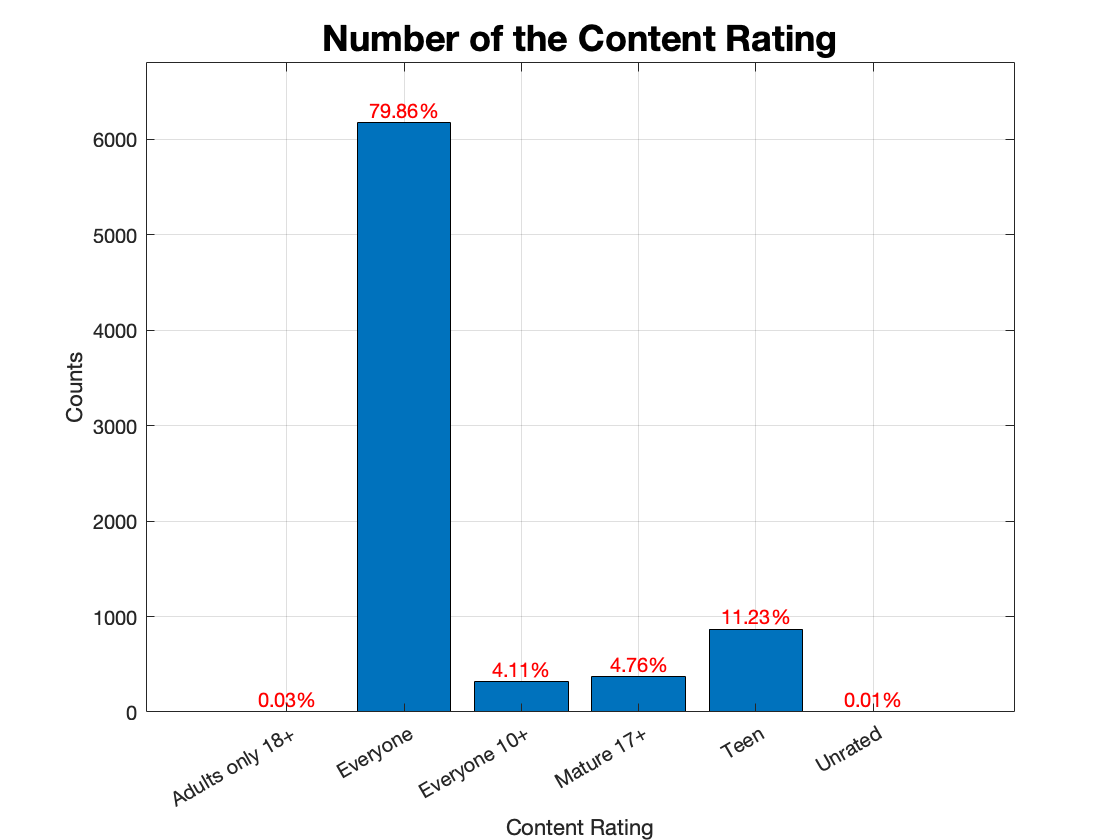


% Content Rating Plot
figure;
big_category_count = countcats(data.ContentRating);
category_name = categories(data.ContentRating);
conten_Rating_count = groupcounts(data,'ContentRating');
figure
b = bar(big_category_count);
xticklabels(category_name);
ylabel('Counts')
ylim([0 6800])
xlabel('Content Rating')
grid on
title('Number of the Content Rating', 'fontsize', 18)
xtips = b.XEndPoints;
ytips = b.YEndPoints;
labels = string(round(conten_Rating_count.Percent,2)) + '%';
text(xtips,ytips,labels,'Color','red','fontsize',10,'HorizontalAlignment','center','VerticalAlignment','bottom')

## Selected pairs of variables one numerical + one categorical

Shayna

(N,C): (rating, category) (rating, type) (rating, content rating) (rating, genre), *Review data was so heavily skewed the graphs look bad so I am skipping it!, (Size, category) (Size, type) (Size, content rating) (Size, genre), (price, category) (price, content rating) (price, genre), *Also skipped installs for the same reason

## Rating and categorical variables

% Most popular cateogires
[n,bin] = hist(data.Category,unique(data.Category));
[~,idx] = sort(-n);
catCounts = n(idx); % The counts for each category sorted
catOrder = bin(idx); % Thier corresponding category sorted
data.Category = categorical(data.Category,catOrder); % categories will be in order of more popular in graph
dataTopCat = data(find(data.Category == catOrder(1) | data.Category == catOrder(2) ...
    | data.Category == catOrder(3) | data.Category == catOrder(4) ...
    | data.Category == catOrder(5) | data.Category == catOrder(6) ...
    | data.Category == catOrder(7) | data.Category == catOrder(8) ...
    | data.Category == catOrder(9) | data.Category == catOrder(10)),:);

% Most popular Genres
[n,bin] = hist(data.Genres,unique(data.Genres));
[~,idx] = sort(-n);
genreCounts = n(idx); % The counts for each category sorted
genreOrder = bin(idx); % Thier corresponding category sorted
data.Genres = categorical(data.Genres,genreOrder); % genres will be in order of more popular in graph
dataTopGenre = data(find(data.Genres == genreOrder(1) | data.Genres == genreOrder(2) ...
    | data.Genres == genreOrder(3) | data.Genres == genreOrder(4) ...
    | data.Genres == genreOrder(5) | data.Genres == genreOrder(6) ...
    | data.Genres == genreOrder(7) | data.Genres == genreOrder(8) ...
    | data.Genres == genreOrder(9) | data.Genres == genreOrder(10)),:);

% create a color bank
c = [97 49 155; 182 89 189; 255 153 214; 204 0 44; 248 160 123; 254 221 11; 145 178 46; 0 184 245; 71 243 255; 0 102 58];
c = c/255;
c3 = c([1,3,5,7,9,10],:);
c2 = c([1,6,10],:);


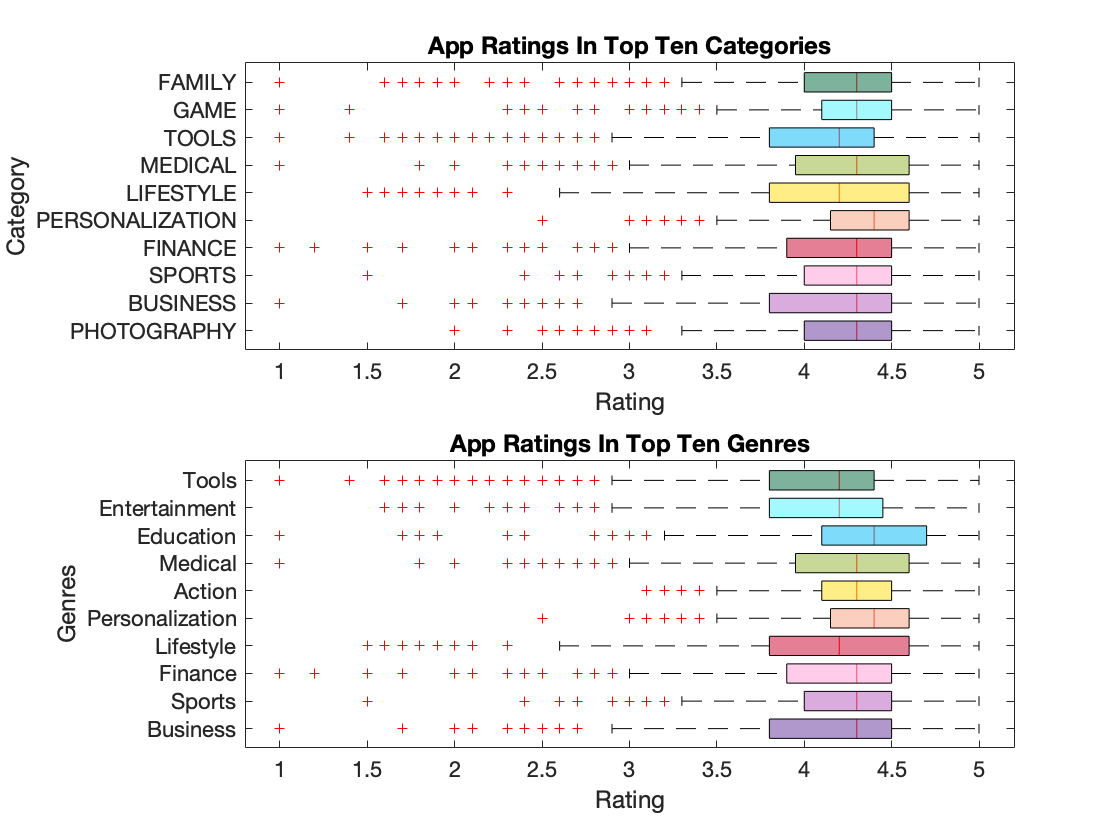

figure;
% Rating v Categories
subplot(2,1,1);
boxplot(dataTopCat.Rating,dataTopCat.Category,'OutlierSize',4,'Widths',0.7,'Orientation','horizontal')
title({"App Ratings In Top Ten Categories"},FontSize=16)
ylabel("Category",FontSize=12)
xlabel("Rating",FontSize=12)
a = get(gca,'XTickLabel');  
set(gca,'XTickLabel',a,'fontsize',11)
set(gca, 'YDir','reverse')
h = findobj(gca,'Tag','Box');
idx = floor([1:10/length(h):10]);
for j=1:length(h)
    patch(get(h(j),'XData'),get(h(j),'YData'),c(idx(j),:),'FaceAlpha',.5);
end

% Rating v Genres
subplot(2,1,2); 
boxplot(dataTopGenre.Rating,dataTopGenre.Genres,'OutlierSize',4,'Widths',0.7,'Orientation','horizontal')
title({"App Ratings In Top Ten Genres"},FontSize=16)
ylabel("Genres",FontSize=12)
xlabel("Rating",FontSize=12)
a = get(gca,'XTickLabel');  
set(gca,'XTickLabel',a,'fontsize',11)
set(gca, 'YDir','reverse')
h = findobj(gca,'Tag','Box');
idx = floor([1:10/length(h):10]);
for j=1:length(h)
    patch(get(h(j),'XData'),get(h(j),'YData'),c(idx(j),:),'FaceAlpha',.5);
end

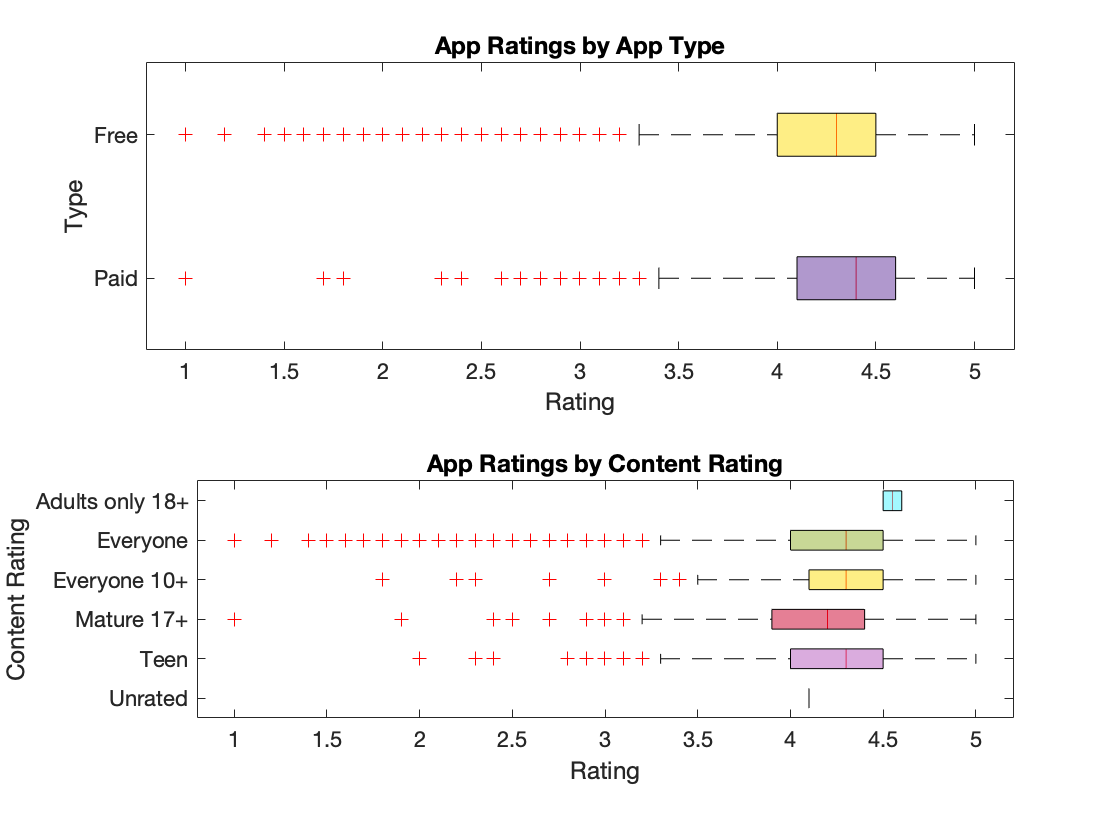

figure;
% Rating v Type
subplot(2,1,1); 
boxplot(data.Rating,data.Type,'Orientation','horizontal')
title({"App Ratings by App Type"},FontSize=14)
ylabel("Type",FontSize=12)
xlabel("Rating",FontSize=12)
a = get(gca,'XTickLabel');  
set(gca,'XTickLabel',a,'fontsize',11)
set(gca, 'YDir','reverse')
h = findobj(gca,'Tag','Box');
idx = floor([1:10/length(h):10]);
for j=1:length(h)
    patch(get(h(j),'XData'),get(h(j),'YData'),c(idx(j),:),'FaceAlpha',.5);
end

% Rating v Content Rating
subplot(2,1,2); 
boxplot(data.Rating,data.ContentRating,'Notch','off','Orientation','horizontal')
title({"App Ratings by Content Rating"},FontSize=14)
ylabel("Content Rating",FontSize=12)
xlabel("Rating",FontSize=12)
a = get(gca,'XTickLabel');  
set(gca,'XTickLabel',a,'fontsize',11)
set(gca, 'YDir','reverse')
h = findobj(gca,'Tag','Box');
idx = floor([1:10/length(h):10]);
for j=1:length(h)
    patch(get(h(j),'XData'),get(h(j),'YData'),c(idx(j),:),'FaceAlpha',.5);
end

### Size and Categorical Variables

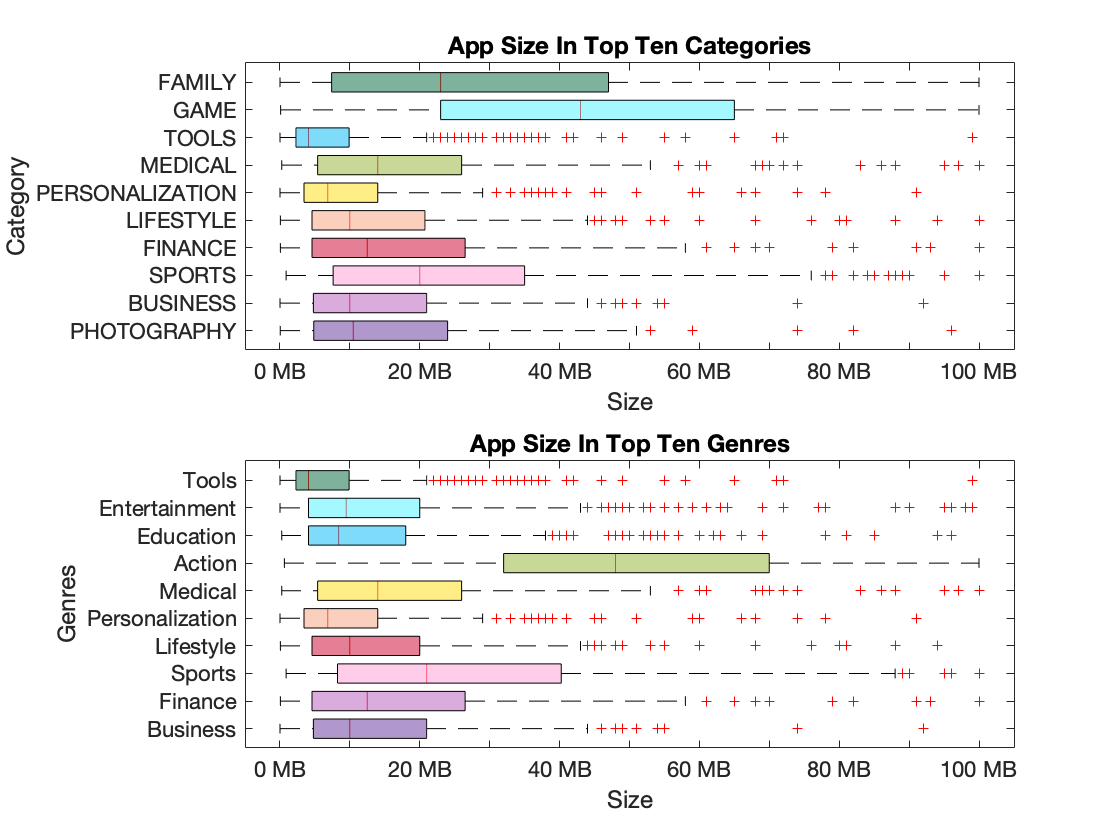

figure;
% Size v Categories
subplot(2,1,1);
boxplot(dataTopCat.Size_MB,dataTopCat.Category,'OutlierSize',4,'Widths',0.7,'Orientation','horizontal')
title({"App Size In Top Ten Categories"},FontSize=16)
ylabel("Category",FontSize=12)
xlabel("Size",FontSize=12)
a = get(gca,'XTickLabel');  
set(gca,'XTickLabel',a,'fontsize',11)
set(gca, 'YDir','reverse')
xtickformat('%g MB')
h = findobj(gca,'Tag','Box');
idx = floor([1:10/length(h):10]);
for j=1:length(h)
    patch(get(h(j),'XData'),get(h(j),'YData'),c(idx(j),:),'FaceAlpha',.5);
end

% Size v Genres
subplot(2,1,2); 
boxplot(dataTopGenre.Size_MB,dataTopGenre.Genres,'OutlierSize',4,'Widths',0.7,'Orientation','horizontal')
title({"App Size In Top Ten Genres"},FontSize=16)
ylabel("Genres",FontSize=12)
xlabel("Size",FontSize=12)
a = get(gca,'XTickLabel');  
set(gca,'XTickLabel',a,'fontsize',11)
set(gca, 'YDir','reverse')
xtickformat('%g MB')
h = findobj(gca,'Tag','Box');
idx = floor([1:10/length(h):10]);
for j=1:length(h)
    patch(get(h(j),'XData'),get(h(j),'YData'),c(idx(j),:),'FaceAlpha',.5);
end

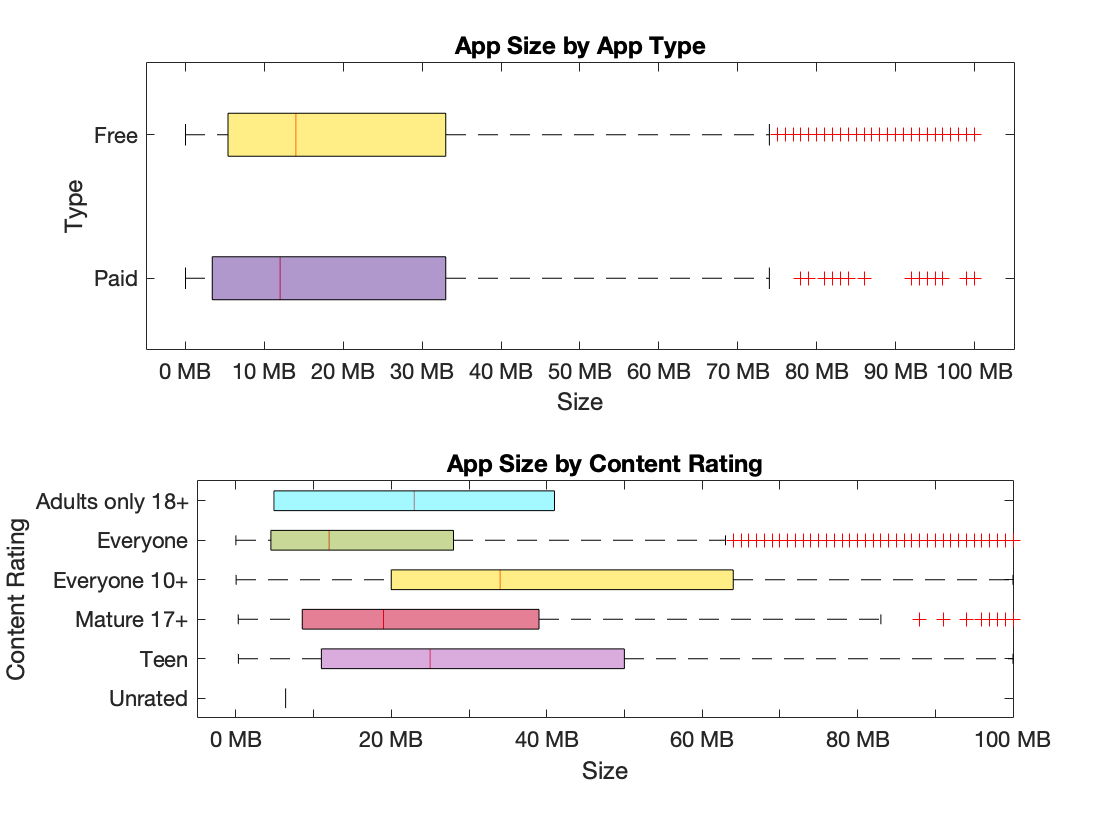

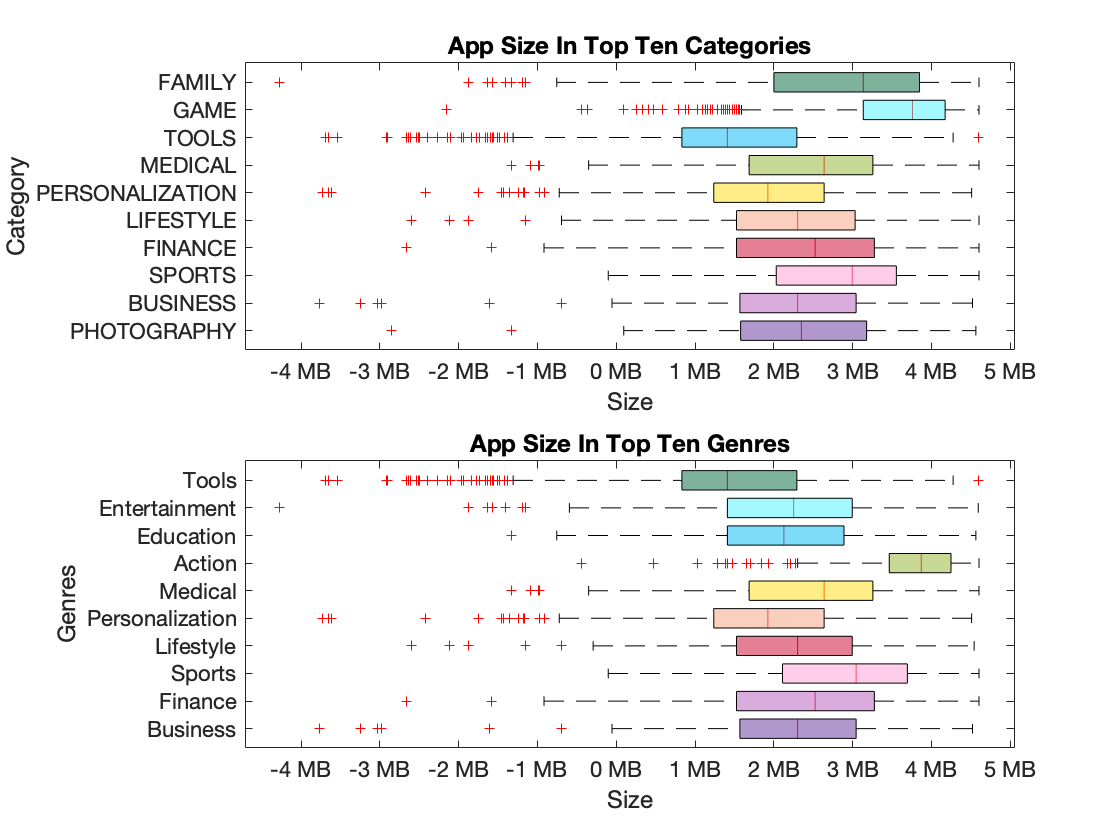

figure;
% Size v Type
subplot(2,1,1); 
boxplot(data.Size_MB,data.Type,'Orientation','horizontal')
title({"App Size by App Type"},FontSize=14)
ylabel("Type",FontSize=12)
xlabel("Size",FontSize=12)
a = get(gca,'XTickLabel');  
set(gca,'XTickLabel',a,'fontsize',11)
set(gca, 'YDir','reverse')
xtickformat('%g MB')
h = findobj(gca,'Tag','Box');
idx = floor([1:10/length(h):10]);
for j=1:length(h)
    patch(get(h(j),'XData'),get(h(j),'YData'),c(idx(j),:),'FaceAlpha',.5);
end

% Size v Content Rating
% idk why this one has negative values.
% min(data.Size_K)
subplot(2,1,2); 
boxplot(data.Size_MB,data.ContentRating,'Orientation','horizontal')
title({"App Size by Content Rating"},FontSize=14)
ylabel("Content Rating",FontSize=12)
xlabel("Size",FontSize=12)
a = get(gca,'XTickLabel');  
set(gca,'XTickLabel',a,'fontsize',11)
set(gca, 'YDir','reverse')
xtickformat('%g MB')
xlim([-5, max(data.Size_MB)]);
h = findobj(gca,'Tag','Box');
idx = floor([1:10/length(h):10]);
for j=1:length(h)
    patch(get(h(j),'XData'),get(h(j),'YData'),c(idx(j),:),'FaceAlpha',.5);
end

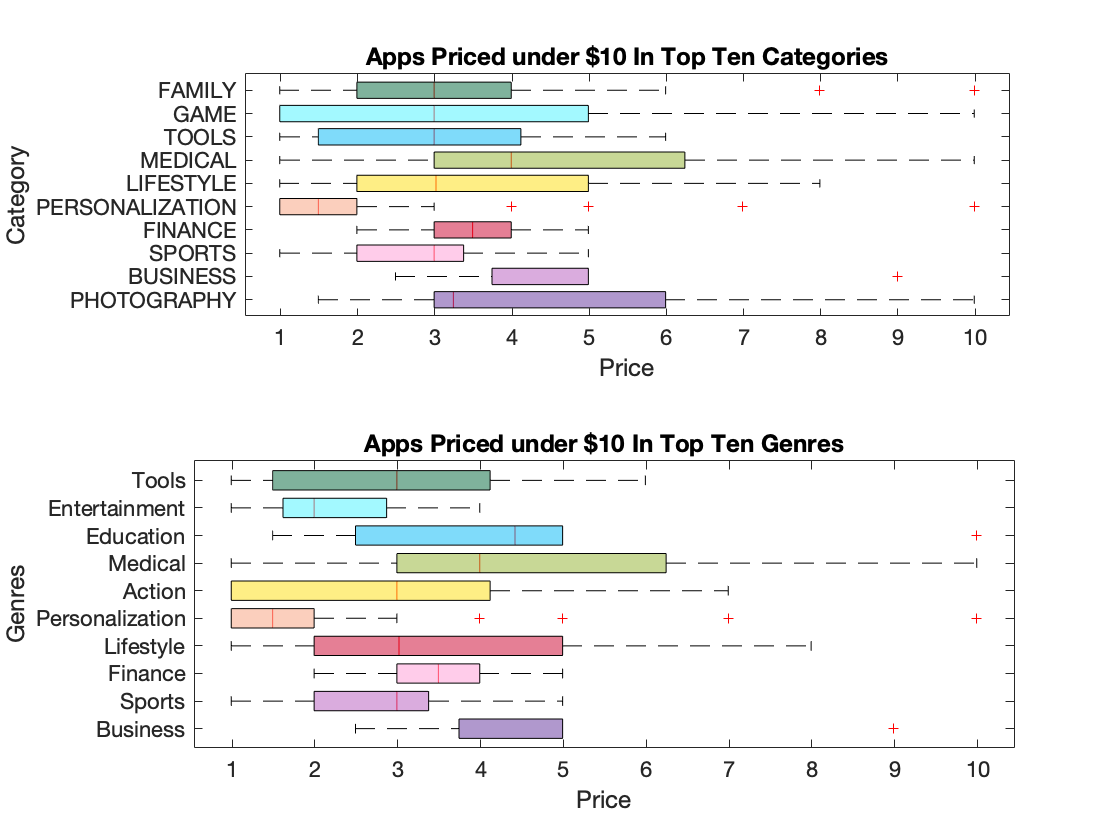

figure;
% Price v Categories
subplot(2,1,1);
boxplot(dataTopCat.Price(find(dataTopCat.Price>0 & dataTopCat.Price<10)),dataTopCat.Category(find(dataTopCat.Price>0 & dataTopCat.Price<10)),'OutlierSize',4,'Widths',0.7,'Orientation','horizontal')
title({"Apps Priced under $10 In Top Ten Categories"},FontSize=16)
ylabel("Category",FontSize=12)
xlabel("Price",FontSize=12)
a = get(gca,'XTickLabel');  
set(gca,'XTickLabel',a,'fontsize',11)
set(gca, 'YDir','reverse')
h = findobj(gca,'Tag','Box');
idx = floor([1:10/length(h):10]);
for j=1:length(h)
    patch(get(h(j),'XData'),get(h(j),'YData'),c(idx(j),:),'FaceAlpha',.5);
end

% Price v Genres
subplot(2,1,2); 
boxplot(dataTopGenre.Price(find(dataTopGenre.Price>0 & dataTopGenre.Price<10)),dataTopGenre.Genres(find(dataTopGenre.Price>0 & dataTopGenre.Price<10)),'OutlierSize',4,'Widths',0.7,'Orientation','horizontal')
title({"Apps Priced under $10 In Top Ten Genres"},FontSize=16)
ylabel("Genres",FontSize=12)
xlabel("Price",FontSize=12)
a = get(gca,'XTickLabel');  
set(gca,'XTickLabel',a,'fontsize',11)
set(gca, 'YDir','reverse')
h = findobj(gca,'Tag','Box');
idx = floor([1:10/length(h):10]);
for j=1:length(h)
    patch(get(h(j),'XData'),get(h(j),'YData'),c(idx(j),:),'FaceAlpha',.5);
end

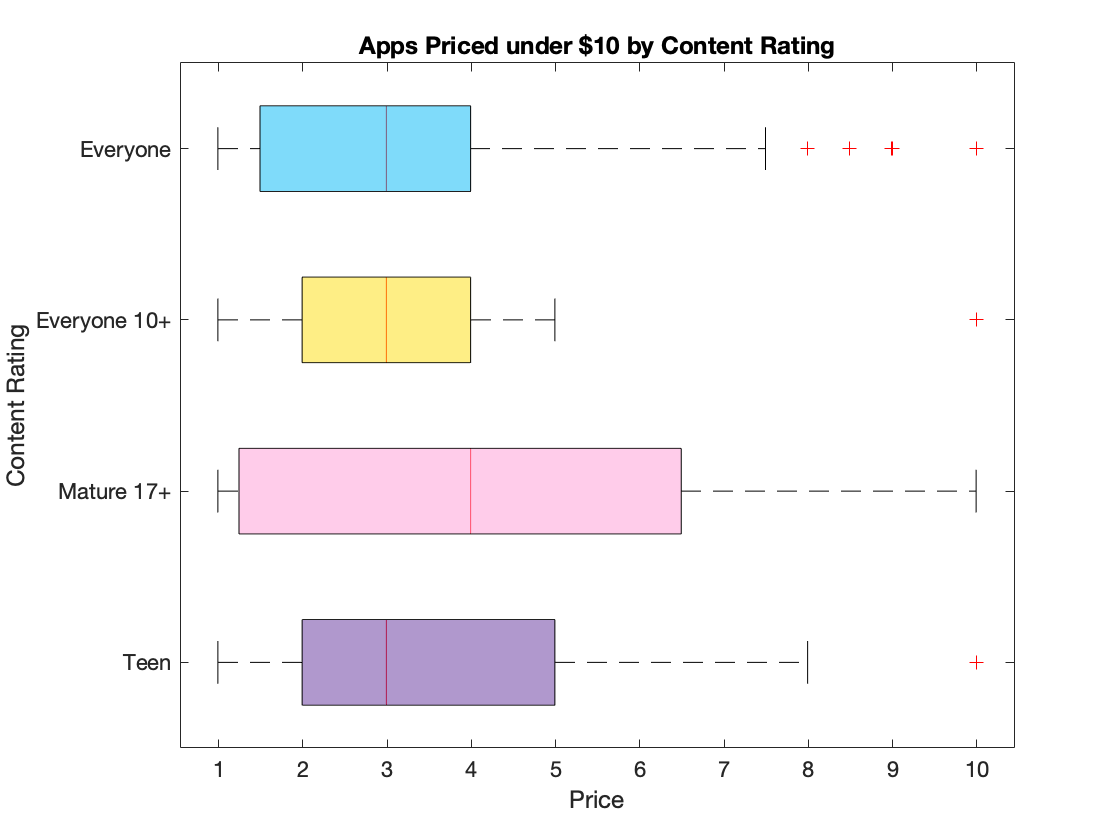


figure;
% Price v Type
boxplot(data.Price(find(data.Price>0 & data.Price<10)), ...
    data.ContentRating(find(data.Price>0 & data.Price<10)), ...
    'Notch','off','Orientation','horizontal')
title({"Apps Priced under $10 by Content Rating"},FontSize=14)
ylabel("Content Rating",FontSize=12)
xlabel("Price",FontSize=12)
a = get(gca,'XTickLabel');  
set(gca,'XTickLabel',a,'fontsize',11)
set(gca, 'YDir','reverse')
h = findobj(gca,'Tag','Box');
idx = floor([1:10/length(h):10]);
for j=1:length(h)
    patch(get(h(j),'XData'),get(h(j),'YData'),c(idx(j),:),'FaceAlpha',.5);
end


% cleaning up
%clear catCounts catOrder dataTopCat dataTopGenre genreCounts genreOrder

Selected triples of variables all numerical (tien)

install = data.Installs/1000000000;
review = data.Reviews/1000000;
size = data.Size_K/1000;

## IMPLEMENT LOG TRANSFORMATION

data.Reviews_log = log(data.Reviews);
data.Size_MB_log = log(data.Size_MB);
data.Installs_log = log(data.Installs);

% need to redo the plots
dataTopCat_log = data(find(data.Category == catOrder(1) | data.Category == catOrder(2) ...
    | data.Category == catOrder(3) | data.Category == catOrder(4) ...
    | data.Category == catOrder(5) | data.Category == catOrder(6) ...
    | data.Category == catOrder(7) | data.Category == catOrder(8) ...
    | data.Category == catOrder(9) | data.Category == catOrder(10)),:);
dataTopGenre_log = data(find(data.Genres == genreOrder(1) | data.Genres == genreOrder(2) ...
    | data.Genres == genreOrder(3) | data.Genres == genreOrder(4) ...
    | data.Genres == genreOrder(5) | data.Genres == genreOrder(6) ...
    | data.Genres == genreOrder(7) | data.Genres == genreOrder(8) ...
    | data.Genres == genreOrder(9) | data.Genres == genreOrder(10)),:);

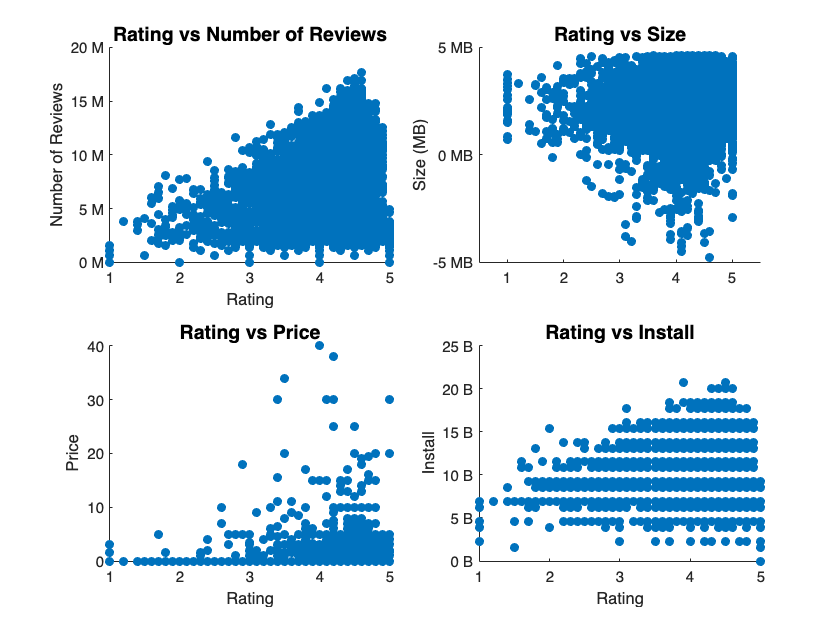


figure;
subplot(2,2,1)
scatter(data.Rating,data.Reviews_log,'filled');
ytickformat('%g M')
xlabel('Rating')
ylabel('Number of Reviews')
title('Rating vs Number of Reviews','fontsize', 13)

subplot(2,2,2)
scatter(data.Rating,data.Size_MB_log,'filled');
title('Rating vs Size','fontsize', 13);
ylabel("Size (MB)")
ytickformat('%g MB')
xlim([0.5 5.5]);

subplot(2,2,3)
scatter(data,"Rating","Price",'filled');
xlabel('Rating')
ylabel('Price')
title('Rating vs Price','fontsize', 13);

subplot(2,2,4)
scatter(data.Rating,data.Installs_log,'filled');
ytickformat('%g B')
xlabel('Rating')
ylabel('Install')
title('Rating vs Install','fontsize', 13);

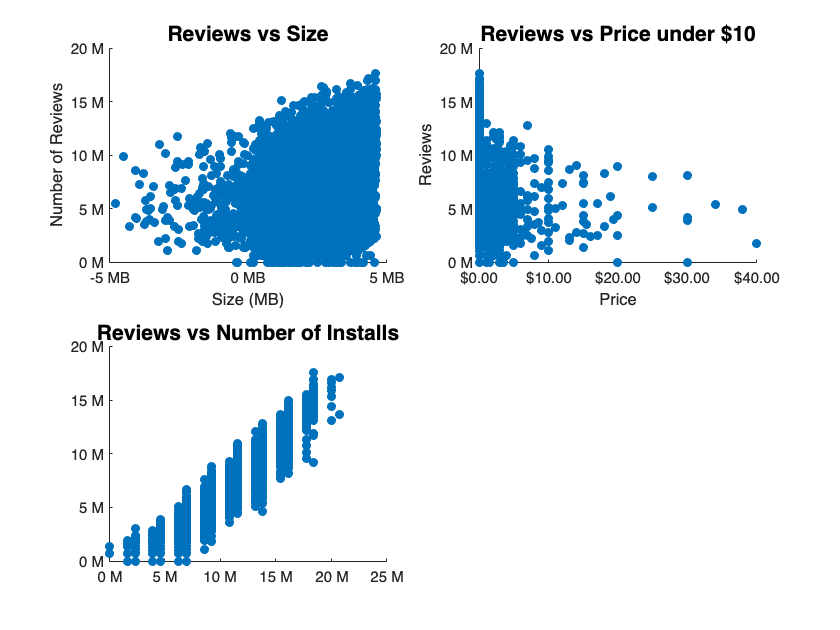


figure;
subplot(2,2,1)
scatter(data.Size_MB_log,data.Reviews_log,'filled');
title('Reviews vs Size','fontsize', 14);
xlabel("Size (MB)")
xtickformat('%g MB')
ytickformat('%g M')
ylabel('Number of Reviews')

subplot(2,2,2) % changed this plot a little too
scatter(data.Price,data.Reviews_log,'filled');
xlabel('Price')
xtickformat('usd')
ytickformat('%g M')
ylabel('Reviews')
title('Reviews vs Price under $10','fontsize', 14);

subplot(2,2,3)
scatter(data.Installs_log,data.Reviews_log,'filled');
title('Reviews vs Number of Installs','fontsize', 14);
xtickformat('%g M')
ytickformat('%g M')

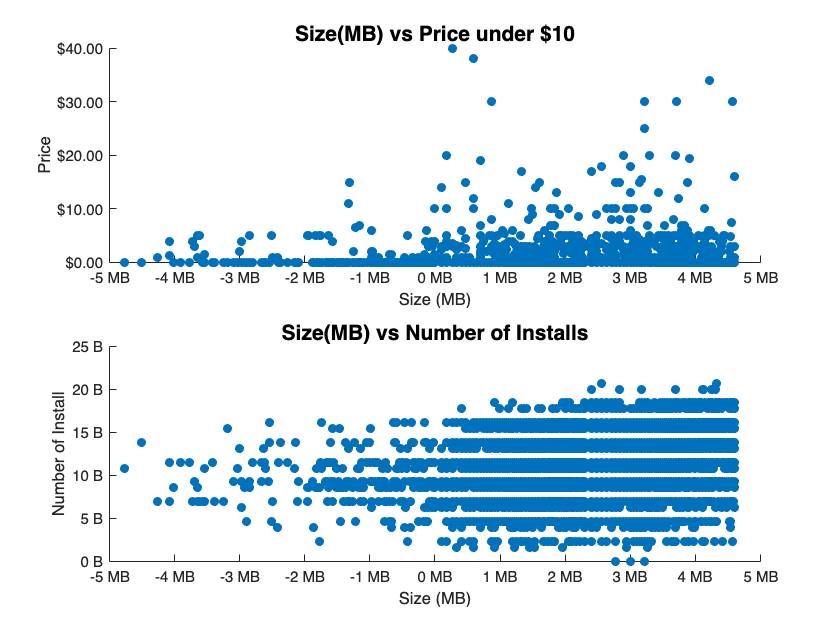

% changed one graph here
figure;
subplot(2,1,1);
scatter(data.Size_MB_log,data.Price,'filled');
xlabel('Size (MB)');
xtickformat('%g MB');
ylabel('Price');
ytickformat('usd');
title('Size(MB) vs Price under $10','fontsize', 14);
subplot(2,1,2)
scatter(data.Size_MB_log,data.Installs_log,'filled');
xlabel('Size (MB)')
xtickformat('%g MB')
ylabel('Number of Install')
ytickformat('%g B')
title('Size(MB) vs Number of Installs','fontsize', 14);

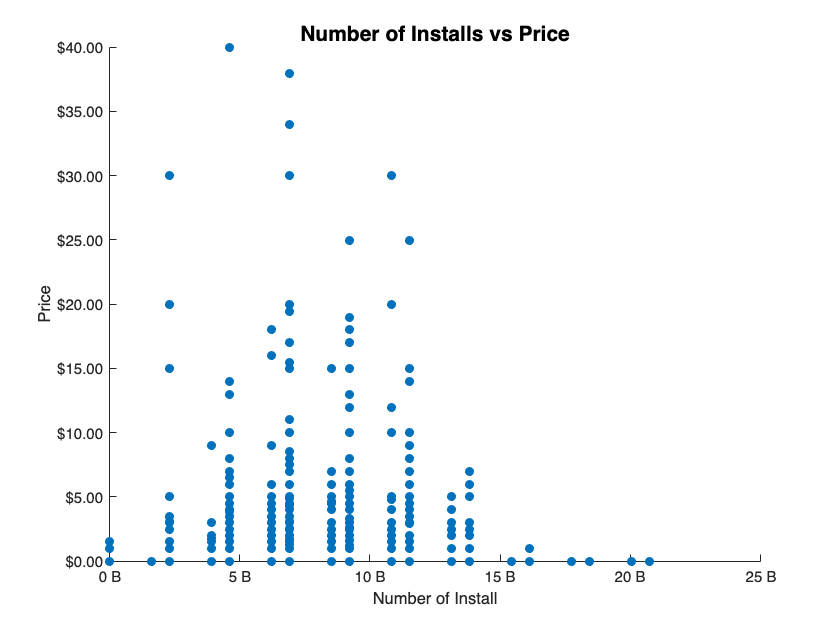

% this graph is so zoomed out lol!
figure;
scatter(data.Installs_log,data.Price,'filled');
xlabel('Number of Install')
xtickformat('%g B')
ylabel('Price')
ytickformat('usd')
title('Number of Installs vs Price','fontsize', 14);

## Selected triples of variables two numerical + one categorical

Shayna

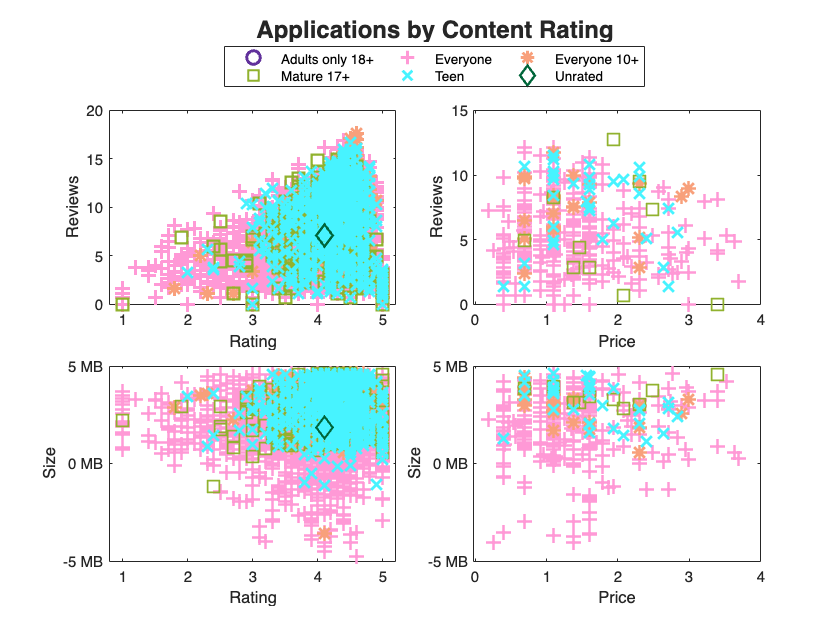

% Content Rating Plot with numeric variables
figure()
t = tiledlayout(2,2,'TileSpacing','compact');
title(t,"Applications by Content Rating",'FontSize',16,'FontWeight','Bold')
c3 = c([1,3,5,7,9,10],:);

ax(1) = nexttile;
h = gscatter(data.Rating,data.Reviews,data.ContentRating,c3,'o+*sxdph^v',10);
set(h,'LineWidth',2)
xlabel('Rating')
ylabel('Reviews')

ax(2) = nexttile;
h = gscatter(data.Price(find(data.Price>0 & data.Price<50)), ...
    data.Reviews(find(data.Price>0 & data.Price<50)), ...
    data.ContentRating(find(data.Price>0 & data.Price<50)),c3,'o+*sxdph^v',10);
set(h,'LineWidth',1.75)
ylabel('Reviews')
xlabel('Price')
hleg = legend(h);
set(hleg,'visible','off');

ax(3) = nexttile;
h = gscatter(data.Rating,data.Size_MB,data.ContentRating,c3,'o+*sxdph^v',10);
set(h,'LineWidth',1.75)
ytickformat('%g MB')
xlabel('Rating')
ylabel('Size')
hleg = legend(h);
set(hleg,'visible','off');

ax(4) = nexttile;
h = gscatter(data.Price(find(data.Price>0 & data.Price<50)), ...
    data.Size_MB(find(data.Price>0 & data.Price<50)), ...
    data.ContentRating(find(data.Price>0 & data.Price<50)),c3,'o+*sxdph^v',10);
set(h,'LineWidth',1.75)
ytickformat('%g MB')
ylabel('Size')
xlabel('Price')
hleg = legend(h);
set(hleg,'visible','off');

ax(4).Colormap = lines(256);
lh =legend(ax(1),'Location','NorthOutside','Orientation','Horizontal','NumColumns',3);
lh.Layout.Tile = 'North'; % <----- relative to tiledlayout

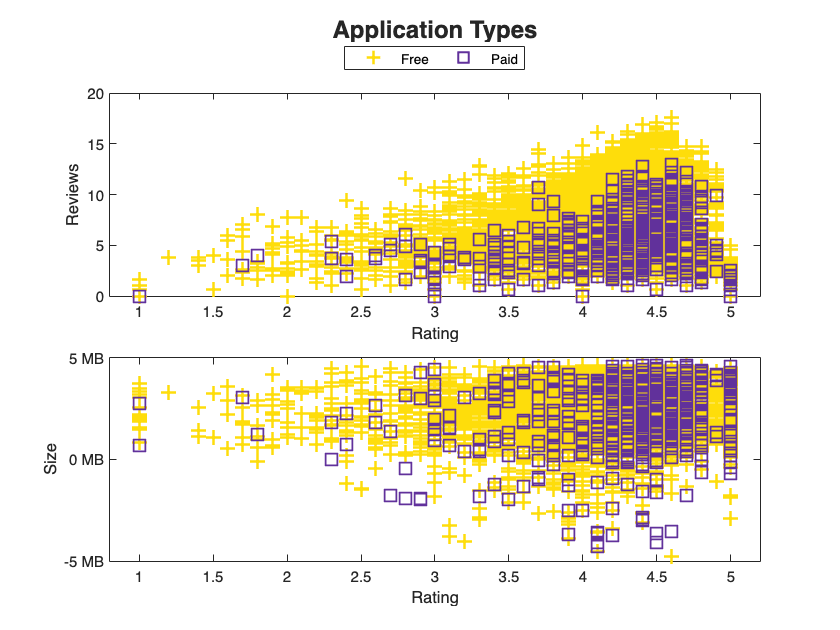

% Type Plot with numeric variables
figure();
t = tiledlayout(2,1,'TileSpacing','compact');
title(t,"Application Types",'FontSize',16,'FontWeight','Bold')

ax(1) = nexttile;
c2 = c([1,6,10],:);
h = gscatter(data.Rating,data.Reviews,data.Type,c2,'o+*sxdph^v',10);
set(h,'LineWidth',1.75)
xlabel('Rating')
ylabel('Reviews')
%hleg = legend(h);
%set(hleg,'visible','off');

ax(2) = nexttile;
h = gscatter(data.Rating,data.Size_MB,data.Type,c2,'o+*sxdph^v',10);
set(h,'LineWidth',1.75)
ytickformat('%g MB')
xlabel('Rating')
ylabel('Size')
hleg = legend(h);
set(hleg,'visible','off');

ax(2).Colormap = lines(256);
lh =legend(ax(1),'Location','NorthOutside','Orientation','Horizontal');
lh.Layout.Tile = 'North'; % <----- relative to tiledlayout

% Categories Plot with numeric variables
figure()
t = tiledlayout(2,2,'TileSpacing','compact');
title(t,"Top 10 Categories",'FontSize',16,'FontWeight','Bold')

ax(1) = nexttile;
h = gscatter(dataTopCat.Rating,dataTopCat.Reviews,dataTopCat.Category,c,'o+*sxdph^v',10);
set(h,'LineWidth',1.75)
xlabel('Rating')
ylabel('Reviews')
hleg = legend(h);
set(hleg,'visible','off');

ax(2) = nexttile;
h = gscatter(dataTopCat.Price(find(dataTopCat.Price>0 & dataTopCat.Price<50)), ...
    dataTopCat.Reviews(find(dataTopCat.Price>0 & dataTopCat.Price<50)), ...
    dataTopCat.Category(find(dataTopCat.Price>0 & dataTopCat.Price<50)),c,'o+*sxdph^v',10);
set(h,'LineWidth',1.75)
ylabel('Reviews')
xlabel('Price')
hleg = legend(h);
set(hleg,'visible','off');

ax(3) = nexttile;
h = gscatter(dataTopCat.Rating,dataTopCat.Size_MB,dataTopCat.Category,c,'o+*sxdph^v',10);

set(h,'LineWidth',1.75)
ytickformat('%g MB')
xlabel('Rating')
ylabel('Size')
hleg = legend(h);
set(hleg,'visible','off');

ax(4) = nexttile;
h = gscatter(dataTopCat.Price(find(dataTopCat.Price>0 & dataTopCat.Price<50)), ...
    dataTopCat.Size_MB(find(dataTopCat.Price>0 & dataTopCat.Price<50)), ...
    dataTopCat.Category(find(dataTopCat.Price>0 & dataTopCat.Price<50)),c,'o+*sxdph^v',10);

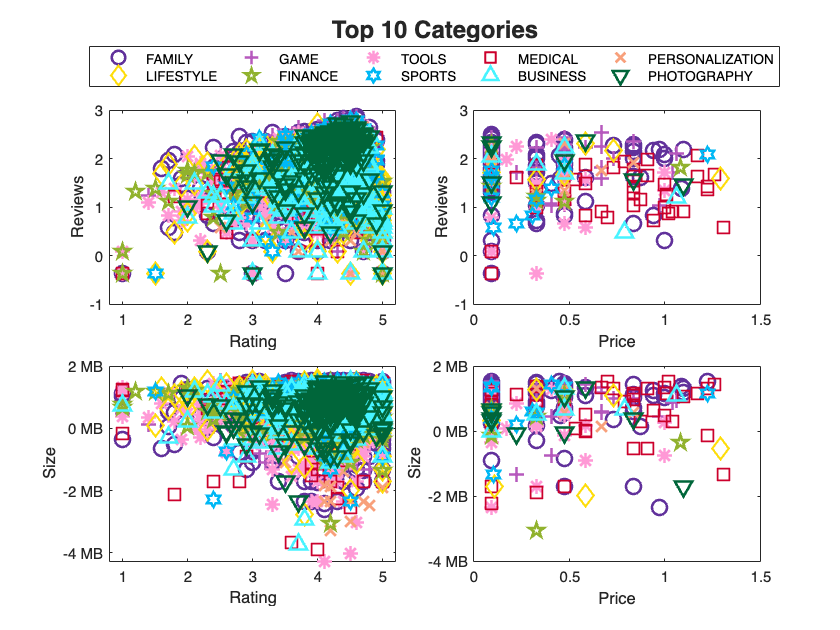

set(h,'LineWidth',1.75)
ytickformat('%g MB')
ylabel('Size')
xlabel('Price')
hleg = legend(h);
set(hleg,'visible','off');

ax(4).Colormap = lines(256);
lh =legend(ax(1),'Location','NorthOutside','Orientation','Horizontal','NumColumns',5);
lh.Layout.Tile = 'North'; % <----- relative to tiledlayout

% Genres Plot with numeric variables
figure()
t = tiledlayout(2,2,'TileSpacing','compact');
title(t,"Top 10 Genres",'FontSize',16,'FontWeight','Bold')

ax(1) = nexttile;
h = gscatter(dataTopGenre.Rating,dataTopGenre.Reviews,dataTopGenre.Genres,c,'o+*sxdph^v',10);
set(h,'LineWidth',1.75)
xlabel('Rating')
ylabel('Reviews')
hleg = legend(h);
set(hleg,'visible','off');

ax(2) = nexttile;
h = gscatter(dataTopGenre.Price(find(dataTopGenre.Price>0 & dataTopGenre.Price<50)), ...
    dataTopGenre.Reviews(find(dataTopGenre.Price>0 & dataTopGenre.Price<50)), ...
    dataTopGenre.Genres(find(dataTopGenre.Price>0 & dataTopGenre.Price<50)),c,'o+*sxdph^v',10);
set(h,'LineWidth',1.75)
ylabel('Reviews')
xlabel('Price')
hleg = legend(h);
set(hleg,'visible','off');

ax(3) = nexttile;
h = gscatter(dataTopGenre.Rating,dataTopGenre.Size_MB,dataTopGenre.Genres,c,'o+*sxdph^v',10);

set(h,'LineWidth',1.75)
ytickformat('%g MB')
xlabel('Rating')
ylabel('Size')
hleg = legend(h);
set(hleg,'visible','off');

ax(4) = nexttile;
h = gscatter(dataTopGenre.Price(find(dataTopGenre.Price>0 & dataTopGenre.Price<50)), ...
    dataTopGenre.Size_MB(find(dataTopGenre.Price>0 & dataTopGenre.Price<50)), ...
    dataTopGenre.Genres(find(dataTopGenre.Price>0 & dataTopGenre.Price<50)),c,'o+*sxdph^v',10);

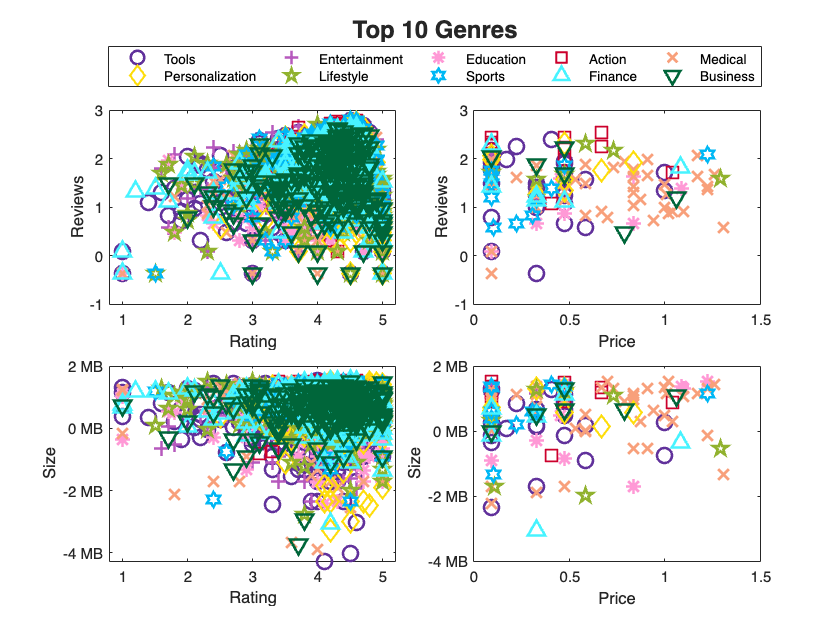

set(h,'LineWidth',1.75)
ytickformat('%g MB')
ylabel('Size')
xlabel('Price')
hleg = legend(h);
set(hleg,'visible','off');

ax(4).Colormap = lines(256);
lh =legend(ax(1),'Location','NorthOutside','Orientation','Horizontal','NumColumns',5);
lh.Layout.Tile = 'North'; % <----- relative to tiledlayout

Getting all numerical data in a matrix and standardizing it

rating, reviews, size, price, installs

X = [data.Rating data.Reviews_log data.Size_MB_log data.Price data.Installs_log];
X_s = (X-mean(X,1))./std(X); % standardize X

## PCA

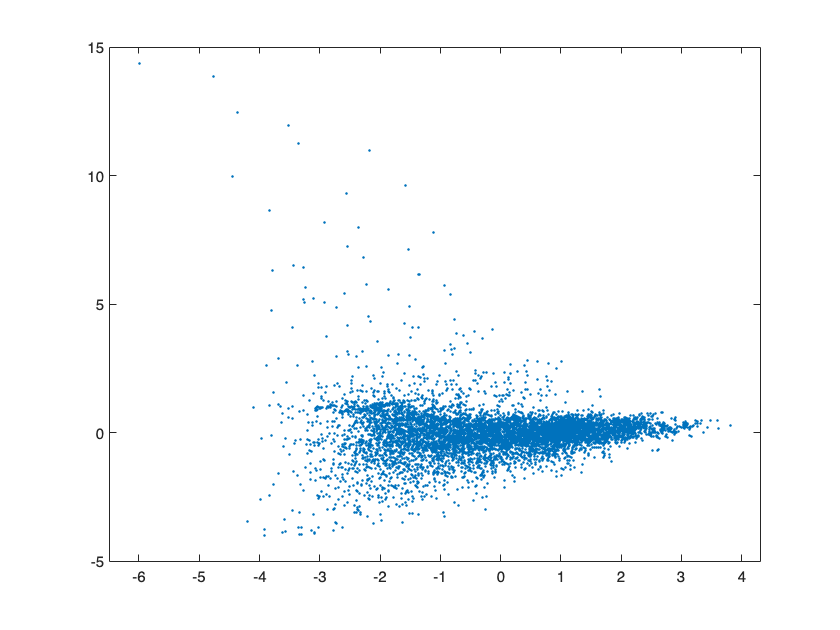

[U, S, V] = svds(X_s);
Y = U .* diag(S)';

% figure;
% semilogy(diag(S),'k')
% title("Singular values")

% figure;
% plot(cumsum(diag(S))/sum(diag(S)),'k')
% title("Cumulitave singular values")

figure;
gscatter(Y(:,1),Y(:,2))

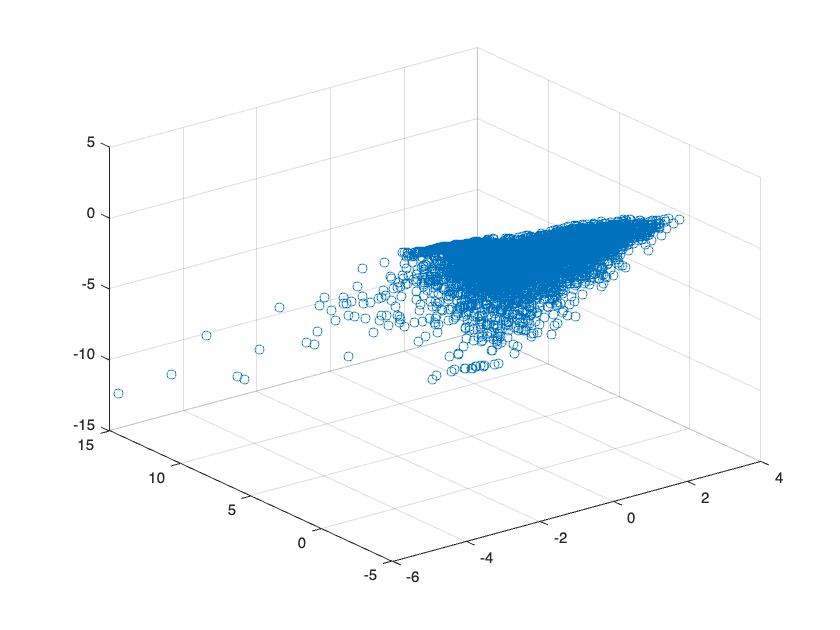

figure;
scatter3(Y(:,1),Y(:,2),Y(:,3))

## LDA

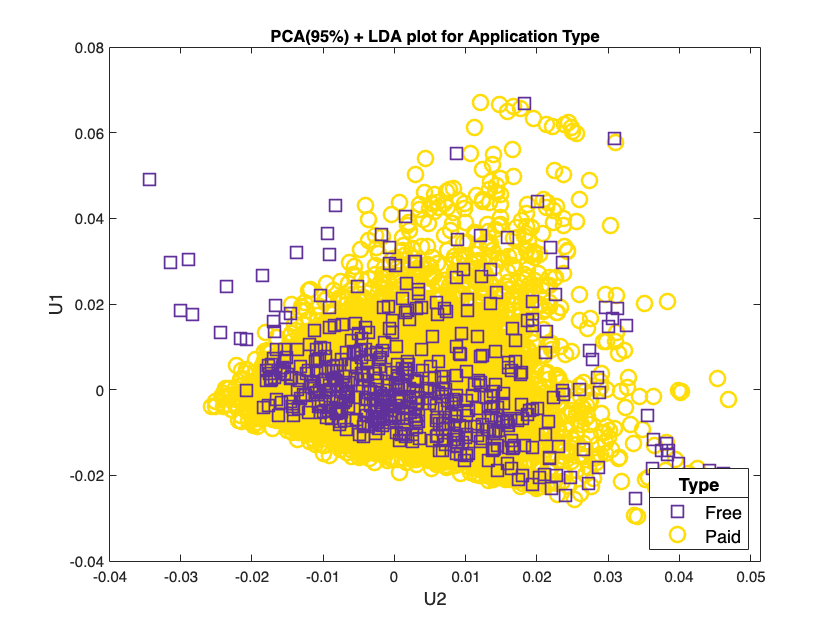

% LDA for Data Type
[V,Y,y_d] = PCALDA(X_s,data.Type,unique(data.Type));
% LDA Plot
figure();
h=gscatter(Y(:,1),Y(:,2),data.Type,c2,'sov',10);
set(h,'LineWidth',1.75)
xlabel('U2','fontsize', 12)
ylabel('U1','fontsize', 12)
title("PCA(95%) + LDA plot for Application Type")
hleg = legend(string(unique(data.Type))','fontsize', 12,'Location','southeast');
htitle = get(hleg,'Title');
set(htitle,'String','Type')

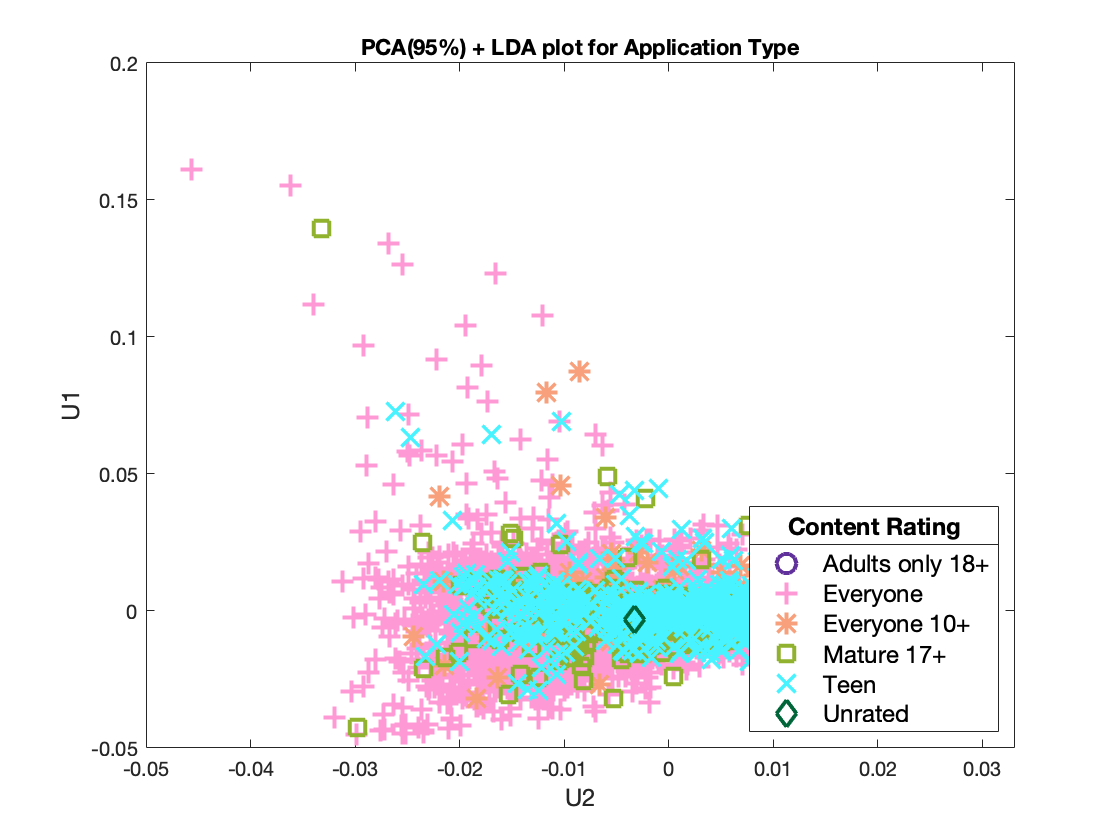


% LDA for Data Type
[V,Y,y_d] = PCALDA(X_s,data.ContentRating,unique(data.ContentRating));
% LDA Plot
figure;
h = gscatter(Y(:,1),Y(:,2),data.ContentRating,c3,'o+*sxdph^v',10);
set(h,'LineWidth',1.75)
xlabel('U2','fontsize', 12)
ylabel('U1','fontsize', 12)
title("PCA(95%) + LDA plot for Application Type")
hleg = legend(string(unique(data.ContentRating))','fontsize', 12,'Location','southeast');
htitle = get(hleg,'Title');
set(htitle,'String','Content Rating')

% LDA for Top 10 Categories
[V,Y,y_d] = PCALDA(X_s,data.Category,unique(dataTopCat.Category));

% LDA Plot
figure;
gscatter(Y(:,1),Y(:,2),y_d,c,'o+*sxdph^v',10);
set(h,'LineWidth',2)

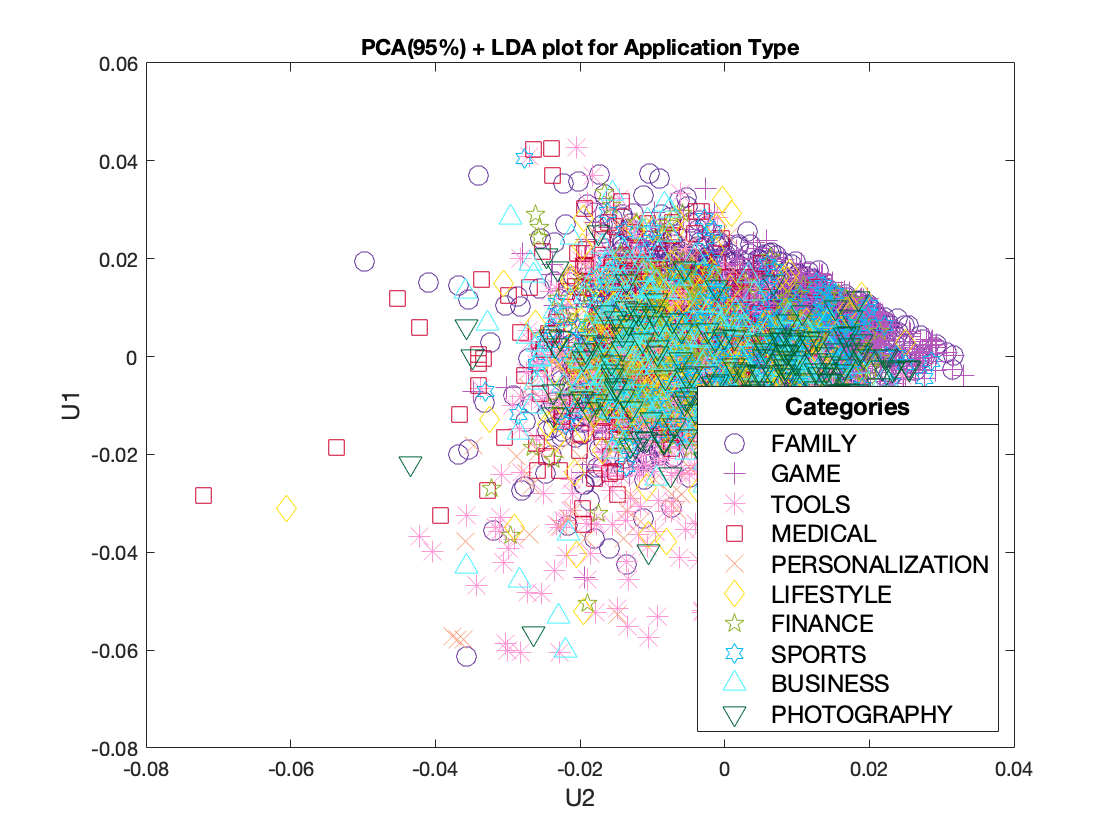

xlabel('U2','fontsize', 12)
ylabel('U1','fontsize', 12)
title("PCA(95%) + LDA plot for Application Type")
hleg = legend(string(unique(dataTopCat.Category))','fontsize', 12,'Location','southeast');
htitle = get(hleg,'Title');
set(htitle,'String','Categories')

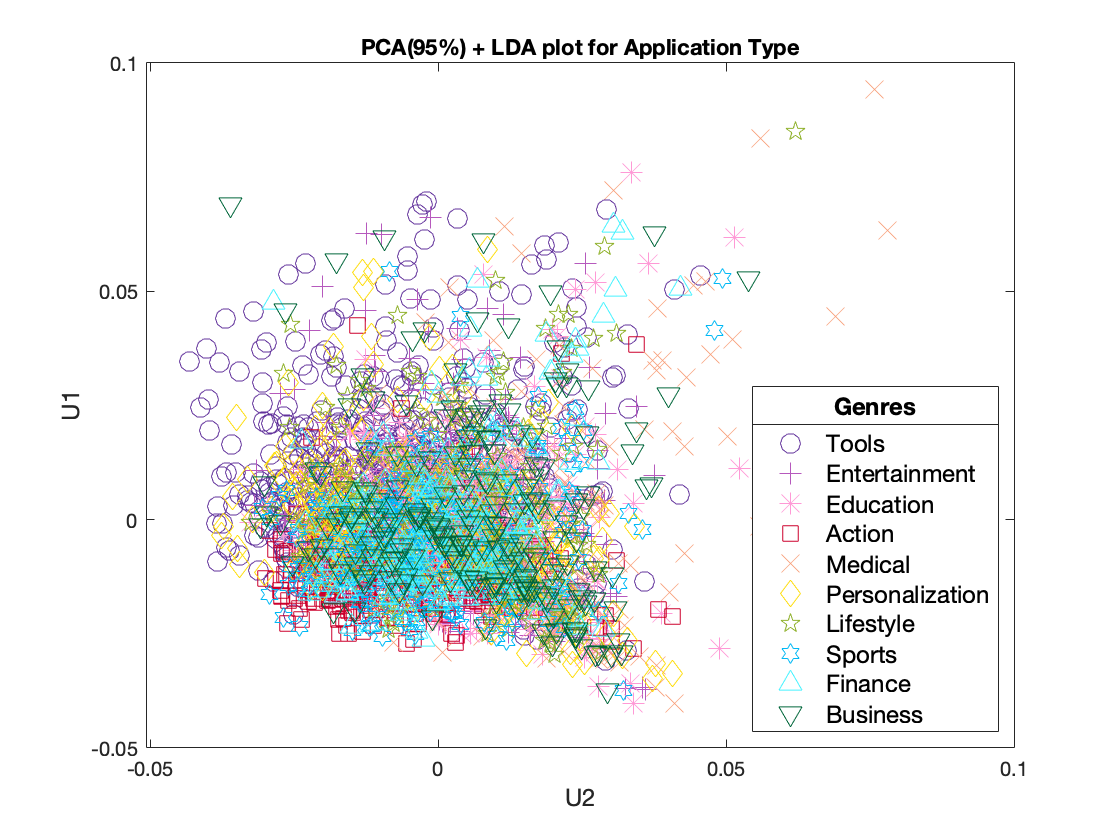

% LDA for Top 10 Genres
[V,Y,y_d] = PCALDA(X_s,data.Genres,unique(dataTopGenre.Genres));
% LDA Plot
figure;
gscatter(Y(:,1),Y(:,2),y_d,c,'o+*sxdph^v',10);
set(h,'LineWidth',2)
xlabel('U2','fontsize', 12)
ylabel('U1','fontsize', 12)
title("PCA(95%) + LDA plot for Application Type")
hleg = legend(string(unique(dataTopGenre.Genres))','fontsize', 12,'Location','southeast');
htitle = get(hleg,'Title');
set(htitle,'String','Genres')

## MDS

% Finding the distances
Da = squareform(pdist(X_s,'cityblock')); % l1
Db = squareform(pdist(X_s,'hamming')); % l2
Dc = squareform(pdist(X_s,'cosine')); % cosine
Dd = squareform(pdist(X_s,'correlation')); % correlation 

Ya = cmdscale(Da,2);
Yb = cmdscale(Db,2);
Yc = cmdscale(Dc,2);
Yd = cmdscale(Dd,2);

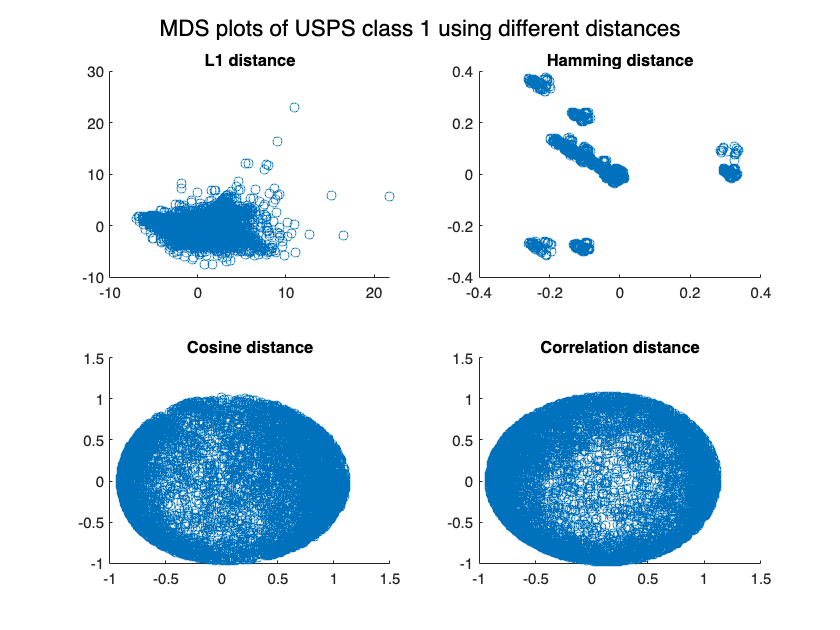

subplot(2,2,1)
scatter(Ya(:,1),Ya(:,2))
title("L1 distance")

subplot(2,2,2)
scatter(Yb(:,1),Yb(:,2))
title("Hamming distance")

subplot(2,2,3)
scatter(Yc(:,1),Yc(:,2))
title("Cosine distance")

subplot(2,2,4)
scatter(Yd(:,1),Yd(:,2))
title("Correlation distance")
sgtitle("MDS plots of USPS class 1 using different distances")

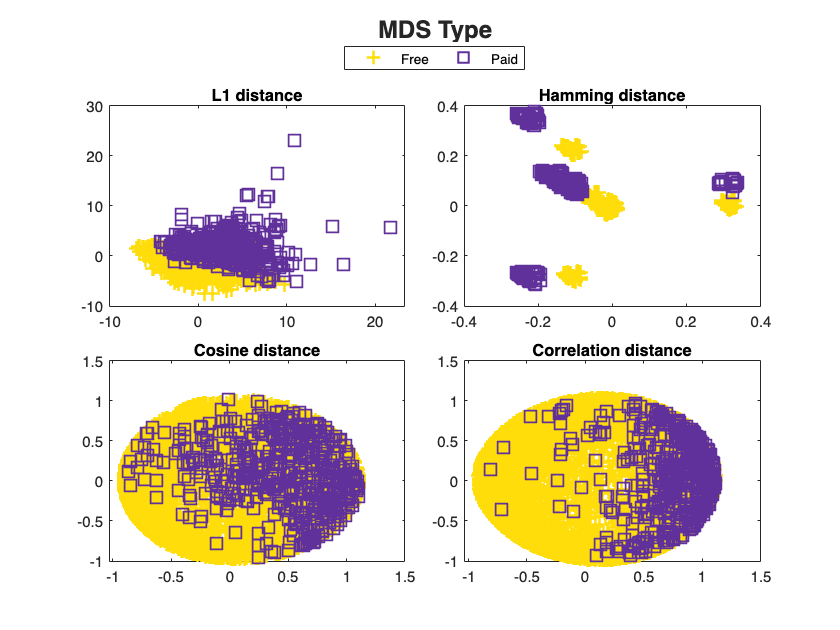

figure
t = tiledlayout(2,2,'TileSpacing','compact');
title(t,"MDS Type",'FontSize',16,'FontWeight','Bold')

ax(1) = nexttile;
h=gscatter(Ya(:,1),Ya(:,2),data.Type,c2,'o+*sxdph^v',10);
set(h,'LineWidth',1.75)
title("L1 distance")

ax(2) = nexttile;
h=gscatter(Yb(:,1),Yb(:,2),data.Type,c2,'o+*sxdph^v',10);
set(h,'LineWidth',1.75)
title("Hamming distance")
hleg = legend(h);
set(hleg,'visible','off');

ax(3) = nexttile;
h=gscatter(Yc(:,1),Yc(:,2),data.Type,c2,'o+*sxdph^v',10);
set(h,'LineWidth',1.75)
title("Cosine distance")
hleg = legend(h);
set(hleg,'visible','off');

ax(4) = nexttile;
h=gscatter(Yd(:,1),Yd(:,2),data.Type,c2,'o+*sxdph^v',10);
set(h,'LineWidth',1.75)
title("Correlation distance")
hleg = legend(h);
set(hleg,'visible','off');

ax(4).Colormap = lines(256);
lh =legend(ax(1),'Location','NorthOutside','Orientation','Horizontal','NumColumns',5);
lh.Layout.Tile = 'North'; % <----- relative to tiledlayout

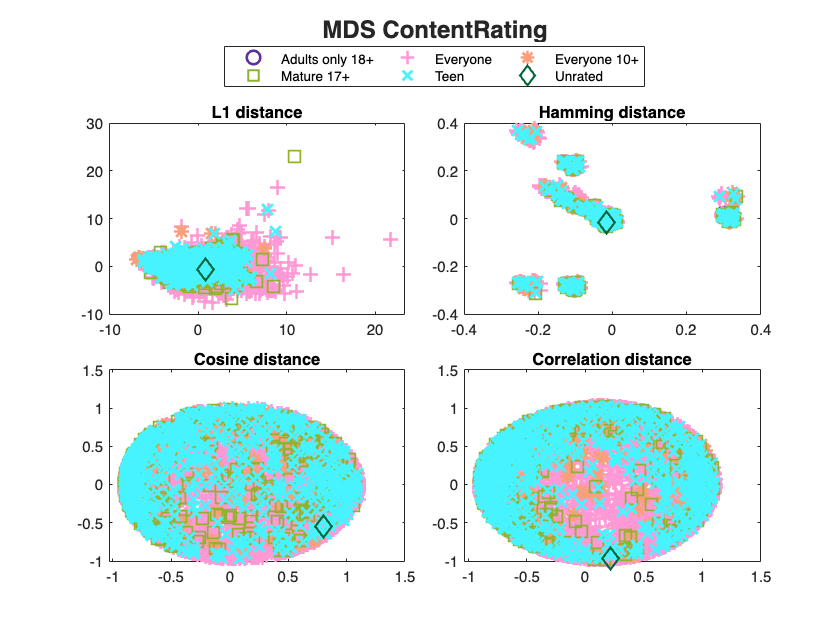

figure
t = tiledlayout(2,2,'TileSpacing','compact');
title(t,"MDS ContentRating",'FontSize',16,'FontWeight','Bold')

ax(1) = nexttile;
h=gscatter(Ya(:,1),Ya(:,2),data.ContentRating,c3,'o+*sxdph^v',10);
set(h,'LineWidth',1.75)
title("L1 distance")

ax(2) = nexttile;
h=gscatter(Yb(:,1),Yb(:,2),data.ContentRating,c3,'o+*sxdph^v',10);
set(h,'LineWidth',1.75)
title("Hamming distance")
hleg = legend(h);
set(hleg,'visible','off');

ax(3) = nexttile;
h=gscatter(Yc(:,1),Yc(:,2),data.ContentRating,c3,'o+*sxdph^v',10);
set(h,'LineWidth',1.75)
title("Cosine distance")
hleg = legend(h);
set(hleg,'visible','off');

ax(4) = nexttile;
h=gscatter(Yd(:,1),Yd(:,2),data.ContentRating,c3,'o+*sxdph^v',10);
set(h,'LineWidth',1.75)
title("Correlation distance")
hleg = legend(h);
set(hleg,'visible','off');

ax(4).Colormap = lines(256);
lh =legend(ax(1),'Location','NorthOutside','Orientation','Horizontal','NumColumns',3);
lh.Layout.Tile = 'North'; % <----- relative to tiledlayout

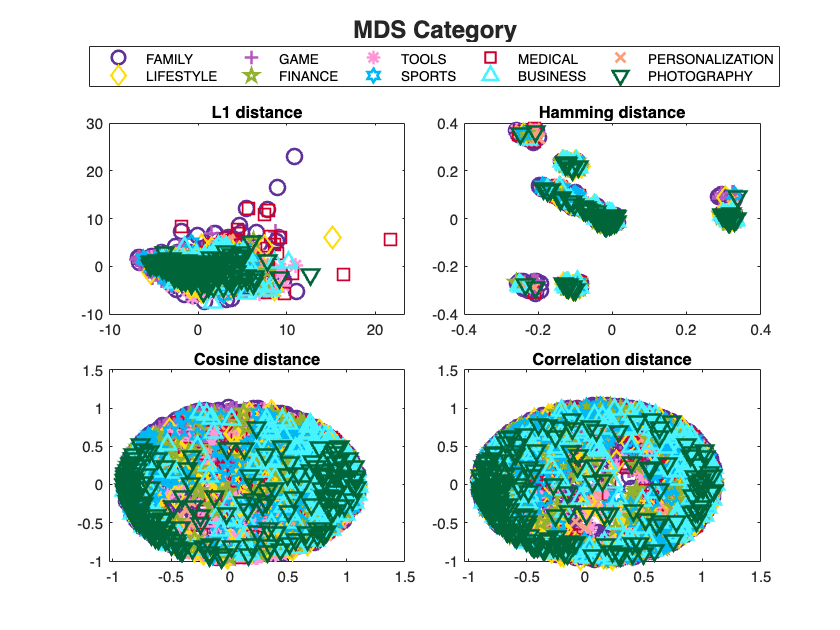

figure
t = tiledlayout(2,2,'TileSpacing','compact');
title(t,"MDS Category",'FontSize',16,'FontWeight','Bold')

ax(1) = nexttile;
h=gscatter(Ya(ismember(data.Category, unique(dataTopCat.Category)),1), ...
    Ya(ismember(data.Category, unique(dataTopCat.Category)),2), ...
    data.Category(ismember(data.Category, unique(dataTopCat.Category))), ...
    c,'o+*sxdph^v',10);
set(h,'LineWidth',1.75)
title("L1 distance")

ax(2) = nexttile;
h=gscatter(Yb(ismember(data.Category, unique(dataTopCat.Category)),1), ...
    Yb(ismember(data.Category, unique(dataTopCat.Category)),2), ...
    data.Category(ismember(data.Category, unique(dataTopCat.Category))), ...
    c,'o+*sxdph^v',10);
set(h,'LineWidth',1.75)
title("Hamming distance")
hleg = legend(h);
set(hleg,'visible','off');

ax(3) = nexttile;
h=gscatter(Yc(ismember(data.Category, unique(dataTopCat.Category)),1), ...
    Yc(ismember(data.Category, unique(dataTopCat.Category)),2), ...
    data.Category(ismember(data.Category, unique(dataTopCat.Category))), ...
    c,'o+*sxdph^v',10);
set(h,'LineWidth',1.75)
title("Cosine distance")
hleg = legend(h);
set(hleg,'visible','off');

ax(4) = nexttile;
h=gscatter(Yd(ismember(data.Category, unique(dataTopCat.Category)),1), ...
    Yd(ismember(data.Category, unique(dataTopCat.Category)),2), ...
    data.Category(ismember(data.Category, unique(dataTopCat.Category))), ...
    c,'o+*sxdph^v',10);
set(h,'LineWidth',1.75)
title("Correlation distance")
hleg = legend(h);
set(hleg,'visible','off');

ax(4).Colormap = lines(256);
lh =legend(ax(1),'Location','NorthOutside','Orientation','Horizontal','NumColumns',5);
lh.Layout.Tile = 'North'; % <----- relative to tiledlayout

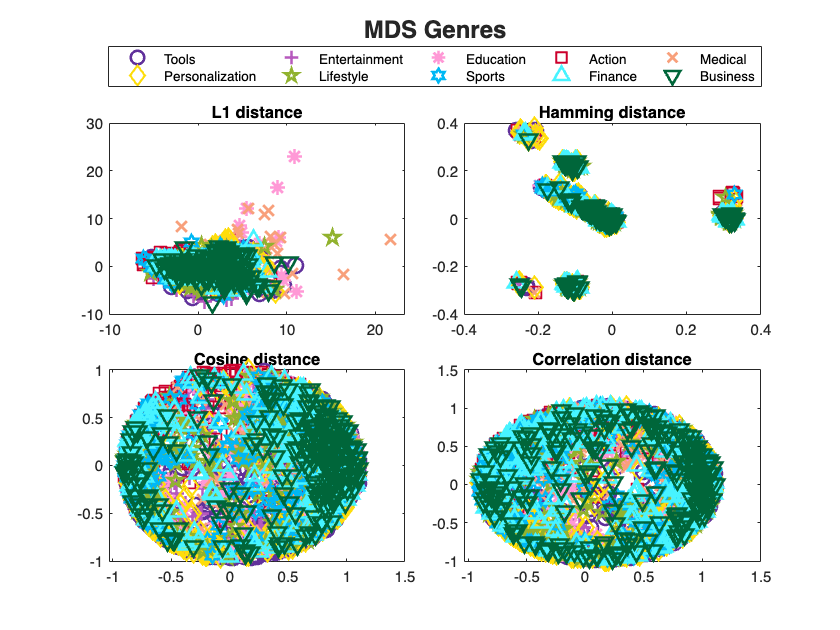

figure
t = tiledlayout(2,2,'TileSpacing','compact');
title(t,"MDS Genres",'FontSize',16,'FontWeight','Bold')

ax(1) = nexttile;
h=gscatter(Ya(ismember(data.Genres, unique(dataTopGenre.Genres)),1), ...
    Ya(ismember(data.Genres, unique(dataTopGenre.Genres)),2), ...
    data.Genres(ismember(data.Genres, unique(dataTopGenre.Genres))), ...
    c,'o+*sxdph^v',10);
set(h,'LineWidth',1.75)
title("L1 distance")

ax(2) = nexttile;
h=gscatter(Yb(ismember(data.Genres, unique(dataTopGenre.Genres)),1), ...
    Yb(ismember(data.Genres, unique(dataTopGenre.Genres)),2), ...
    data.Genres(ismember(data.Genres, unique(dataTopGenre.Genres))), ...
    c,'o+*sxdph^v',10);
set(h,'LineWidth',1.75)
title("Hamming distance")
hleg = legend(h);
set(hleg,'visible','off');

ax(3) = nexttile;
h=gscatter(Yc(ismember(data.Genres, unique(dataTopGenre.Genres)),1), ...
    Yc(ismember(data.Genres, unique(dataTopGenre.Genres)),2), ...
    data.Genres(ismember(data.Genres, unique(dataTopGenre.Genres))), ...
    c,'o+*sxdph^v',10);
set(h,'LineWidth',1.75)
title("Cosine distance")
hleg = legend(h);
set(hleg,'visible','off');

ax(4) = nexttile;
h=gscatter(Yd(ismember(data.Genres, unique(dataTopGenre.Genres)),1), ...
    Yd(ismember(data.Genres, unique(dataTopGenre.Genres)),2), ...
    data.Genres(ismember(data.Genres, unique(dataTopGenre.Genres))), ...
    c,'o+*sxdph^v',10);
set(h,'LineWidth',1.75)
title("Correlation distance")
hleg = legend(h);
set(hleg,'visible','off');

ax(4).Colormap = lines(256);
lh =legend(ax(1),'Location','NorthOutside','Orientation','Horizontal','NumColumns',5);
lh.Layout.Tile = 'North'; % <----- relative to tiledlayout

function [V,Y,y_d] = PCALDA(X,y,d) %input is x and y and a list of unique categorical variables
    x_d = X(ismember(y,d),:);
    y_d = y(ismember(y,d));

    % Perform PCA
    X_cent = x_d - mean(x_d);
    s = svds(X_cent);
    fracs = cumsum(s.^2)/norm(X_cent,"fro")^2;
    k = find(fracs>0.95, 1, "first");
    [U,S] = svds(X_cent,k);
    X_pca = U .* diag(S)';

    % instantiate an empty matrix
    M = [];
    m_d = [];
    n_d = [];
    N = 0;
    for i = size(d,1)
        c = d(i);
        m_dtemp = mean(X_pca(y_d==c,:),1).';
        n_dtemp = sum(y_d==c);
        m_d = [m_d m_dtemp];
        n_d = [n_d n_dtemp];
    end
    % Find the centers of each class
    m = (1/(sum(n_d))).*(sum(n_d.*m_d,2));
    M = sqrt(n_d).*(m_d-m);

    % find sb
    sb = M*M.';
    % Find X tilde for each class
    X_t = X_pca;
    for i=1:size(d,2)
        X_t(y_d==d(i),:) = X_pca(y_d==d(i),:) - m_d(:,i).';
    end

    % find sw
    sw = X_t.' * X_t;

    [V,n] = eigs(sb,sw);
    %V = V./sqrt(sum(v.^2)); % normalize
    Y = X_pca * V;
end